# Laboratorio 5 — Repaso: sistemas lineales y no lineales

**Integrantes:**

**Natalia Vanesa Lopez Diaz 202215351**

**Valentina Garcia Segura 202322115**

clear; close all; format short g
fprintf('Versión de MATLAB: %s\n', version);

Versión de MATLAB: 26.1.0.3346908 (R2026a) Update 5


## Parámetros de personalización

codigo = '202322115';
d = codigo - '0';
assert(numel(d) == 9 && all(d >= 0 & d <= 9), 'El código debe tener exactamente 9 dígitos.');
c = 0.50 + 0.05*d(7);  p = 1 + 0.05*d(7);  q = 1 + 0.05*d(8);  s = 1 + 0.05*d(9);
parametros = table(string(codigo), d(7), d(8), d(9), c, p, q, s, ...
    'VariableNames', {'codigo','d7','d8','d9','c','p','q','s'})

parametros = 1×8 table
      codigo       d7    d8    d9     c       p       q       s  
    ___________    __    __    __    ____    ____    ____    ____

    "202322115"    1     1     5     0.55    1.05    1.05    1.25



tolx = 1e-8;  tolf = 1e-8;  maxit = 100;  tolDer = 1e-12;

## Primer punto. Diagnóstico: ¿qué problema tengo y qué evidencia necesito?

## 1.2 Comprobaciones numéricas

% a. Residuo pequeño con error grande (matriz casi singular)
A12 = [1 1; 1 1+1e-10];  b12 = [2; 2+1e-10];  xMal = [2; 0];      % solución exacta [1; 1]
Rr12a = norm(b12 - A12*xMal, inf)/norm(b12, inf);  Er12a = norm(xMal - [1;1], inf);
fprintf('1.2a  Rr = %.1e pero Er = %.1e  (cond(A) = %.1e, solo verificación)\n', Rr12a, Er12a, cond(A12));

1.2a  Rr = 5.0e-11 pero Er = 1.0e+00  (cond(A) = 4.0e+10, solo verificación)


fprintf('1.2a  f(x) = (x-1)^5 en x = 1.01: residuo = %.1e, error = 1.0e-02\n', abs((1.01 - 1)^5));

1.2a  f(x) = (x-1)^5 en x = 1.01: residuo = 1.0e-10, error = 1.0e-02



% c. Jacobi sin dominancia diagonal
Ac = [2 3; 1 4];  bc = [5; 5];  Dc = diag(diag(Ac));  xj = zeros(2,1);
for k = 1:60, xj = Dc \ (bc - (Ac - Dc)*xj); end
Ad = [1 2; 2 1];  Dd = diag(diag(Ad));
fprintf('1.2c  [2 3;1 4]: rho(BJ) = %.4f, error de Jacobi tras 60 it. = %.1e\n', ...
    max(abs(eig(-Dc\(Ac - Dc)))), norm(xj - [1;1], inf));

1.2c  [2 3;1 4]: rho(BJ) = 0.6124, error de Jacobi tras 60 it. = 1.7e-13


fprintf('1.2c  [1 2;2 1]: rho(BJ) = %.1f (diverge)\n', max(abs(eig(-Dd\(Ad - Dd)))));

1.2c  [1 2;2 1]: rho(BJ) = 2.0 (diverge)



% d. Cambio de signo sin continuidad
o12d = biseccion(@(x) 1./x, -1, 2, tolx, tolf, maxit);
fprintf('1.2d  1/x en [-1,2]: bisección termina en x = %.1e, residuo %.1e, estado = %s\n', ...
    o12d.raiz, o12d.residuo, o12d.estado);

1.2d  1/x en [-1,2]: bisección termina en x = -7.9e-31, residuo 1.3e+30, estado = max_iter



% e. Pivote pequeño sin pivoteo
Ae = [1e-17 1; 1 1];  be = [1; 2];  m21 = Ae(2,1)/Ae(1,1);
x2s = (be(2) - m21*be(1))/(Ae(2,2) - m21*Ae(1,2));  x1s = (be(1) - x2s)/Ae(1,1);
fprintf('1.2e  pivote 1e-17: multiplicador %.0e; sin pivoteo x = [%g, %g], con pivoteo x = [%.4f, %.4f]\n', ...
    m21, x1s, x2s, Ae \ be);

1.2e  pivote 1e-17: multiplicador 1e+17; sin pivoteo x = [0, 1], con pivoteo x = [1.0000, 1.0000]


## Tabla diagnóstica inicial

T1 = table(["a. Ax = b"; "b. x^3-4x+c = 0"; "c. Diodo"; "d. A(alpha)x = b"], ...
    ["Lineal"; "No lineal"; "No lineal (faltan datos)"; "No lineal + lineal (faltan datos)"], ...
    ["A y b; no singularidad, kappa(A) y estructura"; ...
     "c; raíz objetivo; intervalo con cambio de signo o semilla"; ...
     "Vs, R, Is, n, VT y rango físico de VD"; ...
     "h, intervalo o semilla para alpha, forma de A(alpha), b"], ...
    ["Rr y Er pequeños, coherentes con kappa(A)"; ...
     "Ea <= tolx y |f| <= tolf en la raíz buscada"; ...
     "|F| pequeño, VD físico, corrientes consistentes"; ...
     "h(alpha) ~ 0 y Rr pequeño para A(alpha*)"], ...
    ["Pivote nulo o pequeño; kappa(A) grande"; ...
     "Sin cambio de signo; f' ~ 0; convergencia a otra raíz"; ...
     "Overflow de la exponencial; semilla lejana"; ...
     "Raíz alpha espuria; A(alpha) casi singular"], ...
    ["Gauss con pivoteo / LU"; "Bisección + Newton"; "Bisección en [0,Vs] + Newton"; "Newton/bisección + LU"], ...
    'VariableNames', {'Situacion','Tipo','DatosIniciales','CriterioExito','SenalFalla','MetodoInicial'})

T1 = 4×6 table
        Situacion                        Tipo                                          DatosIniciales                                             CriterioExito                                            SenalFalla                                   MetodoInicial         
    __________________    ___________________________________    ___________________________________________________________    _________________________________________________    _______________________________________________________    ______________________________

    "a. Ax = b"           "Lineal"                               "A y b; no singularidad, kappa(A) y estructura"                "Rr y Er pequeños, coherentes con kappa(A)"          "Pivote nulo o pequeño; kappa(A) grande"                   "Gauss con pivoteo / LU"      
    "b. x^3-4x+c = 0"     "No lineal"                            "c; raíz objetivo; intervalo con cambio de signo o semilla"    "Ea <= tolx y |f| <= tolf en la raíz buscad

## Segundo punto. Repaso de métodos para ecuaciones no lineales

f  = @(x) x.^3 - 4*x + c;
df = @(x) 3*x.^2 - 4;

## 2.1 Signos, número de raíces y muestreo con paso 0.1

xP = [-3 -1 0 1 3];
fprintf('Signos en x = [-3 -1 0 1 3]: [%s]\n', num2str(sign(f(xP))));

Signos en x = [-3 -1 0 1 3]: [-1  1  1 -1  1]


x21 = linspace(-3, 3, 61)';  f21 = f(x21);          % paso 0.1 sin acumular redondeo
T21 = table(x21, f21, sign(f21), 'VariableNames', {'x','f(x)','signo'});
nr = ceil(height(T21)/4);                            % impresión compacta en 4 bloques
fprintf('%s\n', repmat('   x      f(x)   sg  |', 1, 4));

   x      f(x)   sg  |   x      f(x)   sg  |   x      f(x)   sg  |   x      f(x)   sg  |


for i = 1:nr
    for k = i:nr:height(T21)
        fprintf('%5.1f %9.3f %+3d  |', x21(k), f21(k), sign(f21(k)));
    end
    fprintf('\n');
end

 -3.0   -14.450  -1  | -1.4     3.406  +1  |  0.2    -0.242  -1  |  1.8    -0.818  -1  |

 -2.9   -12.239  -1  | -1.3     3.553  +1  |  0.3    -0.623  -1  |  1.9    -0.191  -1  |

 -2.8   -10.202  -1  | -1.2     3.622  +1  |  0.4    -0.986  -1  |  2.0     0.550  +1  |

 -2.7    -8.333  -1  | -1.1     3.619  +1  |  0.5    -1.325  -1  |  2.1     1.411  +1  |

 -2.6    -6.626  -1  | -1.0     3.550  +1  |  0.6    -1.634  -1  |  2.2     2.398  +1  |

 -2.5    -5.075  -1  | -0.9     3.421  +1  |  0.7    -1.907  -1  |  2.3     3.517  +1  |

 -2.4    -3.674  -1  | -0.8     3.238  +1  |  0.8    -2.138  -1  |  2.4     4.774  +1  |

 -2.3    -2.417  -1  | -0.7     3.007  +1  |  0.9    -2.321  -1  |  2.5     6.175  +1  |

 -2.2    -1.298  -1  | -0.6     2.734  +1  |  1.0    -2.450  -1  |  2.6     7.726  +1  |

 -2.1    -0.311  -1  | -0.5     2.425  +1  |  1.1    -2.519  -1  |  2.7     9.433  +1  |

 -2.0     0.550  +1  | -0.4     2.086  +1  |  1.2    -2.522  -1  |  2.8    11.302  +1  |

 -1.9     1.291  +1  | -0.3     1.723  +1  |  1.3    -2.453  -1  |  2.9    13.339  +1  |

 -1.8     1.918  +1  | -0.2     1.342  +1  |  1.4    -2.306  -1  |  3.0    15.550  +1  |

 -1.7     2.437  +1  | -0.1     0.949  +1  |  1.5    -2.075  -1  |

 -1.6     2.854  +1  |  0.0     0.550  +1  |  1.6    -1.754  -1  |

 -1.5     3.175  +1  |  0.1     0.151  +1  |  1.7    -1.337  -1  |

idx = find(sign(f21(1:end-1)).*sign(f21(2:end)) < 0);
Tcambios = table(x21(idx), x21(idx+1), f21(idx), f21(idx+1), ...
    'VariableNames', {'x_izq','x_der','f(x_izq)','f(x_der)'})

Tcambios = 3×4 table
    x_izq    x_der    f(x_izq)    f(x_der)
    _____    _____    ________    ________

    -2.1       -2      -0.311        0.55 
     0.1      0.2       0.151      -0.242 
     1.9        2      -0.191        0.55 


raicesRef = sort(real(roots([1 0 -4 c])));  rRef = raicesRef(3);   % roots: solo verificación
fprintf('Raíces de referencia (roots): %.10f, %.10f, %.10f\n', raicesRef);

Raíces de referencia (roots): -2.0654974416, 0.1381592958, 1.9273381457


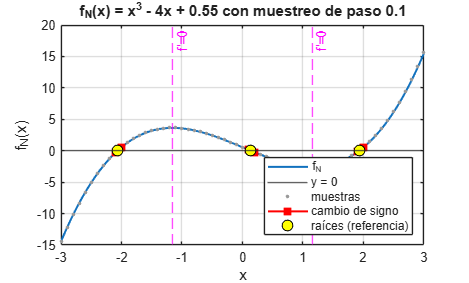

xx = linspace(-3, 3, 600);
theme(figure('Name', '2.1'), 'light');   % tema claro para el PDF
plot(xx, f(xx), 'LineWidth', 1.5); hold on; grid on; yline(0, '-');
plot(x21, f21, '.', 'Color', [0.6 0.6 0.6], 'MarkerSize', 8);
plot([x21(idx) x21(idx+1)]', [f21(idx) f21(idx+1)]', 'rs-', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
plot(raicesRef, zeros(3,1), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
xline([-2 2]/sqrt(3), 'm--', {'f''=0', 'f''=0'});
xlabel('x'); ylabel('f_N(x)');
title(sprintf('f_N(x) = x^3 - 4x + %.2f con muestreo de paso 0.1', c));
legend('f_N', 'y = 0', 'muestras', 'cambio de signo', '', '', 'raíces (referencia)', 'Location', 'southeast');
hold off

## 2.2 Bisección y falsa posición en [1, 3]

fprintf('Predicción: bisección >= %d iteraciones; razón de falsa posición C = %.3f\n', ...
    ceil(log2(2/tolx)), 1 - df(rRef)*(3 - rRef)/f(3));

Predicción: bisección >= 28 iteraciones; razón de falsa posición C = 0.507


oBis = biseccion(f, 1, 3, tolx, tolf, maxit);
oFP  = falsaPosicion(f, 1, 3, tolx, tolf, maxit);
T22 = [filaResumen("Bisección [1,3]", oBis, rRef, raicesRef); ...
       filaResumen("Falsa posición [1,3]", oFP, rRef, raicesRef)];
resumen22 = T22(:, 1:7)

resumen22 = 2×7 table
             Caso              Raiz      Residuo      ErrorPaso     Iter    Evals      Estado   
    ______________________    ______    __________    __________    ____    _____    ___________

    "Bisección [1,3]"         1.9273    2.3607e-10    7.4506e-09     28     "30"     "convergio"
    "Falsa posición [1,3]"    1.9273     5.856e-09    7.9643e-10     32     "34"     "convergio"


disp('Últimas iteraciones de falsa posición:');  disp(tail(oFP.hist(:, 1:6), 3));

Últimas iteraciones de falsa posición:
    n       a       b      x          f(x)            Ea    
    __    ______    _    ______    ___________    __________

    30    1.9273    3    1.9273    -2.2763e-08    3.0959e-09
    31    1.9273    3    1.9273    -1.1546e-08    1.5702e-09
    32    1.9273    3    1.9273     -5.856e-09    7.9643e-10



eFP = abs(oFP.hist.x - rRef);  razFP = eFP(2:end)./eFP(1:end-1);
fprintf('Falsa posición: b fijo en 3 todo el tiempo: %s; razón observada e(n+1)/e(n) = %.3f\n', ...
    string(all(oFP.hist.b == 3)), median(razFP(5:end-2)));

Falsa posición: b fijo en 3 todo el tiempo: true; razón observada e(n+1)/e(n) = 0.507


## 2.3 Punto fijo: dos reformulaciones

g1  = @(x) nthroot(4*x - c, 3);   dg1 = @(x) 4./(3*nthroot(4*x - c, 3).^2);
g2  = @(x) (x.^3 + c)/4;          dg2 = @(x) 3*x.^2/4;
v = linspace(rRef - 0.25, rRef + 0.25, 101);
fprintf('En [x*-0.25, x*+0.25]: |g1''| en [%.3f, %.3f];  |g2''| en [%.3f, %.3f]\n', ...
    min(dg1(v)), max(dg1(v)), min(dg2(v)), max(dg2(v)));

En [x*-0.25, x*+0.25]: |g1'| en [0.329, 0.397];  |g2'| en [2.110, 3.556]


fprintf('g1([1,3]) = [%.3f, %.3f] dentro de [1,3];  max |g1''| en [1,3] = |g1''(1)| = %.3f\n', ...
    g1(1), g1(3), dg1(1));

g1([1,3]) = [1.511, 2.254] dentro de [1,3];  max |g1'| en [1,3] = |g1'(1)| = 0.584


oG1 = puntoFijo(g1, f, 2, tolx, tolf, maxit);
oG2 = puntoFijo(g2, f, 2, tolx, tolf, maxit);
disp('g1, x0 = 2:');  disp(oG1.hist);

g1, x0 = 2:
    n      x_n      g(x_n)    |f(g(x_n))|        Ea            Er    
    __    ______    ______    ___________    __________    __________

     1         2    1.9531        0.1877       0.046926      0.024027
     2    1.9531    1.9365      0.066169       0.016542     0.0085422
     3    1.9365    1.9306      0.023598      0.0058994     0.0030557
     4    1.9306    1.9285     0.0084505      0.0021126     0.0010955
     5    1.9285    1.9278     0.0030307     0.00075768    0.00039304
     6    1.9278    1.9275     0.0010875     0.00027188    0.00014105
     7    1.9275    1.9274    0.00039031     9.7579e-05    5.0627e-05
     8    1.9274    1.9274    0.00014009     3.5024e-05    1.8172e-05
     9    1.9274    1.9273    5.0285e-05     1.2571e-05    6.5226e-06
    10    1.9273    1.9273    1.8049e-05     4.5123e-06    2.3412e-06
    11    1.9273    1.9273    6.4786e-06     1.6196e-06    8.4035e-07
    12    1.9273    1.9273    2.3254e-06     5.8136e-07    3.0164e-07
    13 

disp('g2, x0 = 2:');  disp(oG2.hist);

g2, x0 = 2:
    n     x_n        g(x_n)      |f(g(x_n))|        Ea           Er   
    _    ______    __________    ___________    __________    ________

    1         2        2.1375         1.766         0.1375    0.064327
    2    2.1375         2.579        7.3877        0.44151     0.17119
    3     2.579        4.4259        69.545         1.8469      0.4173
    4    4.4259        21.812         10291         17.386     0.79709
    5    21.812        2594.6    1.7466e+10         2572.8     0.99159
    6    2594.6    4.3666e+09    8.3257e+28     4.3666e+09           1



razG1 = oG1.hist.Ea(2:end)./oG1.hist.Ea(1:end-1);
fprintf('g1: %s en %d it.; razón Ea(n+1)/Ea(n) = %.4f vs |g1''(x*)| = %.4f\n', ...
    oG1.estado, oG1.iter, median(razG1(3:end)), dg1(rRef));

g1: convergio en 18 it.; razón Ea(n+1)/Ea(n) = 0.3589 vs |g1'(x*)| = 0.3589


fprintf('g2: %s en %d it.\n', oG2.estado, oG2.iter);

g2: divergio en 6 it.


oG2b = puntoFijo(g2, f, 0.5, tolx, tolf, maxit);
fprintf('g2 con x0 = 0.5: %s a x = %.8f (raíz central), donde |g2''| = %.3f\n', ...
    oG2b.estado, oG2b.raiz, dg2(raicesRef(2)));

g2 con x0 = 0.5: convergio a x = 0.13815930 (raíz central), donde |g2'| = 0.014


## 2.4 Newton–Raphson y secante

x0N = [2.5, 1.16, 1.15, 2/sqrt(3)];
oN = cell(size(x0N));
for k = 1:numel(x0N)
    oN{k} = newtonRaphson(f, df, x0N(k), tolx, tolf, maxit, tolDer);
end
oSA = secante(f, 1.5, 2.5, tolx, tolf, maxit);
oSB = secante(f, 1.0, 1.3, tolx, tolf, maxit);
disp('Newton, x0 = 2.5:');                           disp(oN{1}.hist(:, [1 2 4 5 6 7]));

Newton, x0 = 2.5:
    n     x_n      f'(x_n)    x_{n+1}     r_{n+1}          Ea    
    _    ______    _______    _______    __________    __________

    1       2.5     14.75     2.0814         1.2411       0.41864
    2    2.0814    8.9961     1.9434        0.11622       0.13796
    3    1.9434    7.3304     1.9275      0.0014614      0.015854
    4    1.9275    7.1463     1.9273     2.4183e-07     0.0002045
    5    1.9273    7.1439     1.9273     6.4393e-15    3.3851e-08
    6    1.9273    7.1439     1.9273     6.6613e-16    8.8818e-16



disp('Newton, x0 = 1.15 (primeras y últimas):');     disp(oN{3}.hist([1:3 end-1:end], [1 2 4 5 6 7]));

Newton, x0 = 1.15 (primeras y últimas):
    n       x_n      f'(x_n)    x_{n+1}     r_{n+1}          Ea    
    __    _______    _______    _______    __________    __________

     1       1.15    -0.0325    -76.669    4.5037e+05        77.819
     2    -76.669      17631    -51.124    1.3342e+05        25.545
     3    -51.124     7837.1      -34.1         39516        17.024
    14    -2.0655     8.7994    -2.0655    1.1679e-08    4.3414e-05
    15    -2.0655     8.7988    -2.0655    2.4425e-15    1.3273e-09



disp('Secante, par A:');                             disp(oSA.hist(:, [1 4 5 6]));

Secante, par A:
    n    x_{n+1}     r_{n+1}          Ea    
    _    _______    __________    __________

    1    1.7515         1.0828       0.74848
    2    1.8632        0.43481       0.11166
    3    1.9381       0.077642      0.074934
    4    1.9268      0.0041348      0.011353
    5    1.9273      3.584e-05    0.00057404
    6    1.9273     1.6803e-08    5.0192e-06
    7    1.9273     6.8168e-14    2.3521e-09



disp('Secante, par B (primeras 5):');                disp(oSB.hist(1:5, [1 4 5 6]));

Secante, par B (primeras 5):
    n    x_{n+1}     r_{n+1}          Ea    
    _    _______    __________    __________

    1      -244     1.4526e+07         245.3
    2       1.3          2.453         245.3
    3    1.3001         2.4529    4.1424e-05
    4    3.5915          32.51        2.2914
    5    1.4608         2.1758        2.1306



fprintf('Newton desde 2/sqrt(3): f''(x0) = %.1e -> %s\n', df(x0N(4)), oN{4}.estado);

Newton desde 2/sqrt(3): f'(x0) = 8.9e-16 -> derivada_pequena


fprintf('Primer salto: Newton 1.16 -> x1 = %.1f;  Newton 1.15 -> x1 = %.1f;  secante B -> x2 = %.0f\n', ...
    oN{2}.hist.("x_{n+1}")(1), oN{3}.hist.("x_{n+1}")(1), oSB.hist.("x_{n+1}")(1));

Primer salto: Newton 1.16 -> x1 = 69.9;  Newton 1.15 -> x1 = -76.7;  secante B -> x2 = -244


lejos = find(oSB.hist.("r_{n+1}") > 1);
[EaMin, kMin] = min(oSB.hist.Ea(lejos));
fprintf('Secante B, iteración %d: Ea = %.1e pero residuo = %.2f  (paso pequeño SIN convergencia)\n', ...
    lejos(kMin), EaMin, oSB.hist.("r_{n+1}")(lejos(kMin)));

Secante B, iteración 3: Ea = 4.1e-05 pero residuo = 2.45  (paso pequeño SIN convergencia)


## Comparación global del punto 2

T2 = [T22; ...
      filaResumen("Punto fijo g1, 2", oG1, rRef, raicesRef); ...
      filaResumen("Punto fijo g2, 2", oG2, rRef, raicesRef); ...
      filaResumen("Newton 2.5", oN{1}, rRef, raicesRef); ...
      filaResumen("Newton 1.16", oN{2}, rRef, raicesRef); ...
      filaResumen("Newton 1.15", oN{3}, rRef, raicesRef); ...
      filaResumen("Newton 2/sqrt(3)", oN{4}, rRef, raicesRef); ...
      filaResumen("Secante (1.5,2.5)", oSA, rRef, raicesRef); ...
      filaResumen("Secante (1.0,1.3)", oSB, rRef, raicesRef)];
resumenMetricas = T2(:, 1:6)

resumenMetricas = 10×6 table
             Caso                Raiz        Residuo      ErrorPaso     Iter     Evals 
    ______________________    __________    __________    __________    ____    _______

    "Bisección [1,3]"             1.9273    2.3607e-10    7.4506e-09     28     "30"   
    "Falsa posición [1,3]"        1.9273     5.856e-09    7.9643e-10     32     "34"   
    "Punto fijo g1, 2"            1.9273    4.9732e-09    1.2433e-09     18     "18"   
    "Punto fijo g2, 2"        4.3666e+09    8.3257e+28    4.3666e+09      6     "6"    
    "Newton 2.5"                  1.9273    6.6613e-16    8.8818e-16      6     "7+6"  
    "Newton 1.16"                 1.9273    6.6613e-16    2.1048e-09     15     "16+15"
    "Newton 1.15"                -2.0655    2.4425e-15    1.3273e-09     15     "16+15"
    "Newton 2/sqrt(3)"            1.1547        2.5292           NaN      0     "1+1"  
    "Secante (1.5,2.5)"           1.9273    6.8168e-14    2.3521e-09      7     "9"    
  

resumenEstados = T2(:, ["Caso", "Estado", "ErrorRef", "RaizAlcanzada"])

resumenEstados = 10×4 table
             Caso                   Estado           ErrorRef     RaizAlcanzada
    ______________________    __________________    __________    _____________

    "Bisección [1,3]"         "convergio"           3.3046e-11     "positiva"  
    "Falsa posición [1,3]"    "convergio"           8.1972e-10     "positiva"  
    "Punto fijo g1, 2"        "convergio"           6.9615e-10     "positiva"  
    "Punto fijo g2, 2"        "divergio"            4.3666e+09     "ninguna"   
    "Newton 2.5"              "convergio"           4.4409e-16     "positiva"  
    "Newton 1.16"             "convergio"           4.4409e-16     "positiva"  
    "Newton 1.15"             "convergio"               3.9928     "negativa"  
    "Newton 2/sqrt(3)"        "derivada_pequena"       0.77264     "ninguna"   
    "Secante (1.5,2.5)"       "convergio"            9.992e-15     "positiva"  
    "Secante (1.0,1.3)"       "convergio"           4.2633e-14     "positiva"  


seqs = {oBis.hist.x, oFP.hist.x, oG1.hist.("g(x_n)"), [2.5; oN{1}.hist.("x_{n+1}")], ...
        [1.5; 2.5; oSA.hist.("x_{n+1}")]};
[pEst, razEst] = cellfun(@(xs) ordenConvergencia(xs, rRef), seqs);
Torden = table(["Bisección"; "Falsa posición"; "Punto fijo g1"; "Newton (2.5)"; "Secante A"], ...
    pEst', razEst', 'VariableNames', {'Metodo','OrdenEstimado','RazonMedia'})

Torden = 5×3 table
         Metodo         OrdenEstimado    RazonMedia
    ________________    _____________    __________

    "Bisección"            1.4431          0.45081 
    "Falsa posición"            1           0.5162 
    "Punto fijo g1"             1          0.35878 
    "Newton (2.5)"          1.943         0.015593 
    "Secante A"            1.5928         0.066084 


## Figura 1: residuo frente a iteración

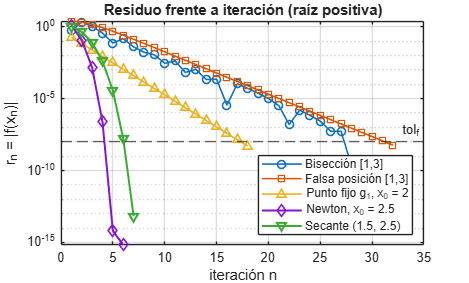

piso = 1e-16;                                        % los residuos nulos se dibujan en 1e-16
theme(figure('Name', 'Figura 1'), 'light');
semilogy(oBis.hist.n, max(abs(oBis.hist.("f(x)")), piso), 'o-', 'LineWidth', 1.2); hold on; grid on
semilogy(oFP.hist.n,  max(abs(oFP.hist.("f(x)")),  piso), 's-', 'LineWidth', 1.2);
semilogy(oG1.hist.n,  max(oG1.hist.("|f(g(x_n))|"), piso), '^-', 'LineWidth', 1.2);
semilogy(oN{1}.hist.n, max(oN{1}.hist.("r_{n+1}"), piso), 'd-', 'LineWidth', 1.5);
semilogy(oSA.hist.n,  max(oSA.hist.("r_{n+1}"), piso), 'v-', 'LineWidth', 1.5);
yline(tolf, '--', 'tol_f');
xlabel('iteración n'); ylabel('r_n = |f(x_n)|');
legend('Bisección [1,3]', 'Falsa posición [1,3]', 'Punto fijo g_1, x_0 = 2', ...
    'Newton, x_0 = 2.5', 'Secante (1.5, 2.5)', 'Location', 'southeast');
title('Residuo frente a iteración (raíz positiva)'); hold off

## Figura 2: sensibilidad y fallas por datos iniciales

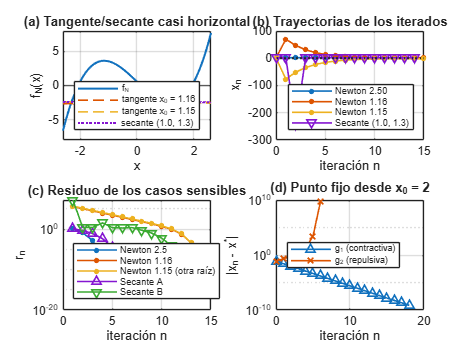

figuraSensibilidad(f, df, x0N, oN, oSA, oSB, oG1, oG2, raicesRef, rRef);

## Resumen cuantitativo del punto 2

fprintf('GARANTÍA:     bisección %d it. y falsa posición %d it. (%s); g1 %s en %d it.; g2 %s\n', ...
    oBis.iter, oFP.iter, oBis.estado, oG1.estado, oG1.iter, oG2.estado);

GARANTÍA:     bisección 28 it. y falsa posición 32 it. (convergio); g1 convergio en 18 it.; g2 divergio


fprintf('VELOCIDAD:    orden: FP %.2f, g1 %.2f, Newton %.2f, secante %.2f\n', pEst(2:5));

VELOCIDAD:    orden: FP 1.00, g1 1.00, Newton 1.94, secante 1.59


fprintf('              razón media: bisección %.2f, FP %.2f, g1 %.2f\n', razEst(1:3));

              razón media: bisección 0.45, FP 0.52, g1 0.36


fprintf('SENSIBILIDAD: Newton 2.5 -> %d it.; 1.16 -> %d it.; 1.15 -> raíz %.4f (%s)\n', ...
    oN{1}.iter, oN{2}.iter, oN{3}.raiz, oN{3}.estado);

SENSIBILIDAD: Newton 2.5 -> 6 it.; 1.16 -> 15 it.; 1.15 -> raíz -2.0655 (convergio)


fprintf('              Newton 2/sqrt(3) -> %s; secante A %d it. vs B %d it.\n', ...
    oN{4}.estado, oSA.iter, oSB.iter);

              Newton 2/sqrt(3) -> derivada_pequena; secante A 7 it. vs B 13 it.


fprintf('COSTO:        evaluaciones: bisección %d, FP %d, g1 %d (g) + %d (f), Newton %d (f) + %d (f''), secante %d\n', ...
    oBis.nevalf, oFP.nevalf, oG1.iter, oG1.nevalf, oN{1}.nevalf, oN{1}.nevaldf, oSA.nevalf);

COSTO:        evaluaciones: bisección 30, FP 34, g1 18 (g) + 18 (f), Newton 7 (f) + 6 (f'), secante 9


## Actualización parcial de la tabla diagnóstica (fila b)

evidencia = repmat("Pendiente (puntos 3-6)", height(T1), 1);
evidencia(2) = sprintf(['3 raíces reales. Bisección %d it., FP %d it. (b fijo), g1 %d it., g2 diverge.\n' ...
    'Newton(2.5) %d it., Newton(1.15) -> raíz %.3f; secante A %d it., B %d it.'], ...
    oBis.iter, oFP.iter, oG1.iter, oN{1}.iter, oN{3}.raiz, oSA.iter, oSB.iter);
T1 = addvars(T1, evidencia, 'NewVariableNames', 'Evidencia');
fprintf('Fila b (%s; método inicial: %s). Evidencia:\n%s\n', T1.Tipo(2), T1.MetodoInicial(2), T1.Evidencia(2));

Fila b (No lineal; método inicial: Bisección + Newton). Evidencia:
3 raíces reales. Bisección 28 it., FP 32 it. (b fijo), g1 18 it., g2 diverge.
Newton(2.5) 6 it., Newton(1.15) -> raíz -2.065; secante A 7 it., B 13 it.


## Tercer punto. Repaso de métodos directos para sistemas lineales

## 3.1 Inspección de A y solución de referencia

A = [5+p, -1,   0,   1;
     -1,  5+q, -1,   0;
      0,  -1,  4+s, -1;
      1,   0,  -1,   5];
b = [6 + 0.1*d(7); -8 - 0.1*d(8); 9 + 0.1*d(9); 1.5];

diag31 = abs(diag(A));  fuera31 = sum(abs(A), 2) - diag31;
T31 = table((1:4)', diag(A), fuera31, diag31 > fuera31, diag31./fuera31, ...
    'VariableNames', {'Fila','a_ii','Suma_|a_ij|_j~=i','Dominante','Cociente'})

T31 = 4×5 table
    Fila    a_ii    Suma_|a_ij|_j~=i    Dominante    Cociente
    ____    ____    ________________    _________    ________

     1      6.05           2              true        3.025  
     2      6.05           2              true        3.025  
     3      5.25           2              true        2.625  
     4         5           2              true          2.5  


fprintf('Dimensión: %dx%d | simétrica: %d | no nulos: %d de %d (%.1f %%)\n', ...
    size(A), issymmetric(A), nnz(A), numel(A), 100*nnz(A)/numel(A));

Dimensión: 4x4 | simétrica: 1 | no nulos: 12 de 16 (75.0 %)


fprintf('Diagonal positiva: %d | fuera de la diagonal: valores en {%s}\n', ...
    all(diag(A) > 0), num2str(unique(A(~eye(4)))'));

Diagonal positiva: 1 | fuera de la diagonal: valores en {-1  0  1}


fprintf('Magnitudes: max|a_ii| = %.2f, min|a_ii| = %.2f, max|a_ij| (i~=j) = %.2f\n', ...
    max(diag31), min(diag31), max(abs(A(~eye(4)))));

Magnitudes: max|a_ii| = 6.05, min|a_ii| = 5.00, max|a_ij| (i~=j) = 1.00


fprintf('Pivotes de Gauss sin intercambios (predicción de pivoteo): primer pivote a11 = %.2f\n', A(1,1));

Pivotes de Gauss sin intercambios (predicción de pivoteo): primer pivote a11 = 6.05


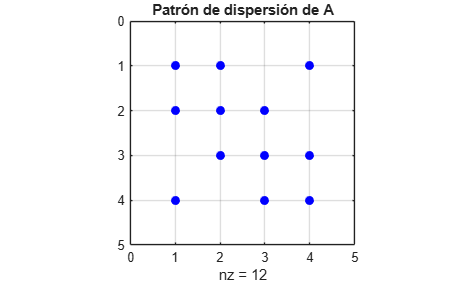


theme(figure('Name', '3.1'), 'light');
spy(A, 'b', 20); title('Patrón de dispersión de A'); grid on


xref = A\b                                           % referencia (después de la predicción)

xref =       0.77422
     -0.92547
       1.7267
      0.49049


## 3.2 Gauss simple, pivoteo parcial y pivoteo parcial escalonado

metodos3 = ["Gauss simple"; "Pivoteo parcial"; "Pivoteo parcial escalonado"];
solvers3 = {@gaussSimple, @(M, v) gaussPivoteo(M, v, "parcial"), @(M, v) gaussPivoteo(M, v, "escalonado")};

T32 = tablaDirectos(metodos3, solvers3, A, b, xref)

T32 = 3×8 table
               Metodo                   Ea            Er            Rr        MaxMult    Intercambios      Estado      PasoFalla
    ____________________________    __________    __________    __________    _______    ____________    __________    _________

    "Gauss simple"                  1.1102e-16    6.4299e-17    1.8698e-16    0.19132         0          "resuelto"       NaN   
    "Pivoteo parcial"               1.1102e-16    6.4299e-17    1.8698e-16    0.19132         0          "resuelto"       NaN   
    "Pivoteo parcial escalonado"    1.1102e-16    6.4299e-17    1.8698e-16    0.19132         0          "resuelto"       NaN   



P0 = eye(4);  P0 = P0([3 2 1 4], :);
A0 = P0*A;  b0 = P0*b;
disp('A0 = P0*A:');  disp(A0);

A0 = P0*A:
            0           -1         5.25           -1
           -1         6.05           -1            0
         6.05           -1            0            1
            1            0           -1            5



fprintf('Primer pivote de A0: a11 = %g\n', A0(1,1));

Primer pivote de A0: a11 = 0



T32P0 = tablaDirectos(metodos3, solvers3, A0, b0, xref)

T32P0 = 3×8 table
               Metodo                   Ea            Er            Rr        MaxMult    Intercambios       Estado        PasoFalla
    ____________________________    __________    __________    __________    _______    ____________    _____________    _________

    "Gauss simple"                         NaN           NaN           NaN          0         0          "pivote_nulo"         1   
    "Pivoteo parcial"               1.1102e-16    6.4299e-17    1.8698e-16    0.19132         1          "resuelto"          NaN   
    "Pivoteo parcial escalonado"    1.1102e-16    6.4299e-17    1.8698e-16    0.19132         1          "resuelto"          NaN   


[~, infoGS0] = gaussSimple(A0, b0);
fprintf('Gauss simple sobre A0: estado = %s en el paso k = %d\n', infoGS0.estado, infoGS0.pasoFalla);

Gauss simple sobre A0: estado = pivote_nulo en el paso k = 1


## 3.3 Sistema mal escalado

S = diag([1e-6 1 1e4 1]);
As = S*A;  bs = S*b;
kappaA3 = cond(A);  kappaAs = cond(As);              % cond: solo verificación
fprintf('kappa(A) = %.4f  |  kappa(As) = %.4e\n', kappaA3, kappaAs);

kappa(A) = 1.9338  |  kappa(As) = 9.8827e+09


disp('As = S*A:');  disp(As);

As = S*A:
     6.05e-06       -1e-06            0        1e-06
           -1         6.05           -1            0
            0       -10000        52500       -10000
            1            0           -1            5




T33 = tablaDirectos(metodos3, solvers3, As, bs, xref);
T33.Rr_original = arrayfun(@(i) norm(b - A*solvers3{i}(As, bs), inf)/norm(b, inf), (1:3)');
T33

T33 = 3×9 table
               Metodo                   Ea            Er            Rr         MaxMult      Intercambios      Estado      PasoFalla    Rr_original
    ____________________________    __________    __________    __________    __________    ____________    __________    _________    ___________

    "Gauss simple"                  1.1102e-16    6.4299e-17    1.8698e-20    1.6529e+05         0          "resuelto"       NaN       1.8698e-16 
    "Pivoteo parcial"                4.774e-15    2.7648e-15    6.3107e-20             1         3          "resuelto"       NaN       2.6178e-15 
    "Pivoteo parcial escalonado"    1.1102e-16    6.4299e-17    1.8698e-20    1.6529e+05         0          "resuelto"       NaN       1.8698e-16 



[~, iMinR33] = min(T33.Rr);  [~, iMinE33] = min(T33.Ea);
fprintf('Menor residuo (sistema escalado): %s (Rr = %.2e, Ea = %.2e)\n', ...
    T33.Metodo(iMinR33), T33.Rr(iMinR33), T33.Ea(iMinR33));

Menor residuo (sistema escalado): Gauss simple (Rr = 1.87e-20, Ea = 1.11e-16)


fprintf('Menor error respecto a xref:     %s (Rr = %.2e, Ea = %.2e)\n', ...
    T33.Metodo(iMinE33), T33.Rr(iMinE33), T33.Ea(iMinE33));

Menor error respecto a xref:     Gauss simple (Rr = 1.87e-20, Ea = 1.11e-16)


fprintf('¿Coinciden el menor residuo y el menor error? %s\n', string(iMinR33 == iMinE33));

¿Coinciden el menor residuo y el menor error? true


fprintf('Factores de amplificación Er/Rr: %s\n', num2str((T33.Er./T33.Rr)', '%10.2e'));

Factores de amplificación Er/Rr: 3.44e+03  4.38e+04  3.44e+03


## 3.4 Factorización PA = LU y reutilización para varios vectores

[L34, U34, P34, info34] = luPivoteo(A);
errLU = norm(P34*A - L34*U34, inf)/norm(A, inf);
fprintf('||PA - LU||_inf / ||A||_inf = %.3e  |  intercambios = %d  |  max|l_ij| = %.4f\n', ...
    errLU, info34.nInter, info34.maxMult);

||PA - LU||_inf / ||A||_inf = 0.000e+00  |  intercambios = 0  |  max|l_ij| = 0.1913


disp('L ='); disp(L34);  disp('U ='); disp(U34);  disp('P ='); disp(P34);

L =
            1            0            0            0
     -0.16529            1            0            0
            0     -0.16993            1            0
      0.16529     0.028088     -0.19132            1

U =
         6.05           -1            0            1
            0       5.8847           -1      0.16529
            0            0       5.0801     -0.97191
            0            0            0       4.6441

P =
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1




[Lm, Um, Pm] = lu(A);                                % lu de MATLAB: solo verificación
fprintf('Diferencia con lu de MATLAB: ||L-Lm|| = %.1e, ||U-Um|| = %.1e, ||P-Pm|| = %.1e\n', ...
    norm(L34 - Lm, inf), norm(U34 - Um, inf), norm(P34 - Pm, inf));

Diferencia con lu de MATLAB: ||L-Lm|| = 0.0e+00, ||U-Um|| = 0.0e+00, ||P-Pm|| = 0.0e+00



b2 = b;  b2([1 3]) = 1.05*b([1 3]);                  % componentes 1 y 3 aumentadas 5 %
b3 = b;  b3([2 4]) = 1.05*b([2 4]);                  % componentes 2 y 4 aumentadas 5 %
B34 = [b, b2, b3];
disp('Vectores b, b2, b3:');  disp(B34);

Vectores b, b2, b3:
          6.1        6.405          6.1
         -8.1         -8.1       -8.505
          9.5        9.975          9.5
          1.5          1.5        1.575




nB = size(B34, 2);
[EaLU, EaG, difLUG, RrLU, RrG] = deal(zeros(nB, 1));
for j = 1:nB
    bj = B34(:, j);  xrefj = A\bj;
    xLU = resolverLU(L34, U34, P34, bj);
    xG  = gaussPivoteo(A, bj, "parcial");
    EaLU(j) = norm(xLU - xrefj, inf);    EaG(j) = norm(xG - xrefj, inf);
    RrLU(j) = norm(bj - A*xLU, inf)/norm(bj, inf);
    RrG(j)  = norm(bj - A*xG, inf)/norm(bj, inf);
    difLUG(j) = norm(xLU - xG, inf);
end
T34 = table(["b"; "b2"; "b3"], EaLU, EaG, RrLU, RrG, difLUG, ...
    'VariableNames', {'Vector','Ea_LU','Ea_Gauss','Rr_LU','Rr_Gauss','||xLU-xGauss||'})

T34 = 3×6 table
    Vector      Ea_LU        Ea_Gauss       Rr_LU        Rr_Gauss     ||xLU-xGauss||
    ______    __________    __________    __________    __________    ______________

     "b"      1.1102e-16    1.1102e-16    1.8698e-16    1.8698e-16          0       
     "b2"     1.1102e-16    1.1102e-16    3.5616e-16    3.5616e-16          0       
     "b3"     1.1102e-16    1.1102e-16    9.3492e-17    9.3492e-17          0       



n34 = size(A, 1);  k34 = 1:n34-1;
opsFact  = sum((n34 - k34) + 2*(n34 - k34).^2);      % factorización: divisiones + productos/sumas
opsSust  = n34*(n34 - 1) + n34^2;                    % sustitución progresiva (L unitaria) + regresiva
opsGauss = opsFact + sum(2*(n34 - k34)) + n34^2;     % eliminación completa con b + regresiva
tFact  = timeit(@() luPivoteo(A));
tSust  = timeit(@() resolverLU(L34, U34, P34, b2));
tGauss = timeit(@() gaussPivoteo(A, b2, "parcial"));
T34costo = table(["Reutilizar L, U, P"; "Repetir eliminación"], ...
    [opsFact + nB*opsSust; nB*opsGauss], [tFact + nB*tSust; nB*tGauss], ...
    'VariableNames', {'Estrategia', sprintf('Operaciones_%d_vectores', nB), sprintf('Tiempo_s_%d_vectores', nB)})

T34costo = 2×3 table
         Estrategia          Operaciones_3_vectores    Tiempo_s_3_vectores
    _____________________    ______________________    ___________________

    "Reutilizar L, U, P"              118                  3.4053e-05     
    "Repetir eliminación"             186                  4.5252e-05     


fprintf('Por vector adicional: %d operaciones (LU reutilizada) frente a %d (eliminación completa)\n', ...
    opsSust, opsGauss);

Por vector adicional: 28 operaciones (LU reutilizada) frente a 62 (eliminación completa)


fprintf('Asintóticamente: 2n^2 frente a 2n^3/3 por vector; para n = 1000: %.0f veces menos operaciones\n', ...
    (2*1000^3/3)/(2*1000^2));

Asintóticamente: 2n^2 frente a 2n^3/3 por vector; para n = 1000: 333 veces menos operaciones


## Punto 4: Métodos iterativos, condicionamiento y criterios de convergencia.

**4.1**

d = [2 0 2 3 2 2 1 1 5];

d7 = d(7);
d8 = d(8);
d9 = d(9);

p = 1 + 0.05*d7;
q = 1 + 0.05*d8;
s = 1 + 0.05*d9;

% Sistema base
A = [5+p, -1,   0,  1;
    -1,  5+q, -1,  0;
    0,  -1,  4+s, -1;
    1,   0,  -1,  5];

b = [6 + 0.1*d7;
    -8 - 0.1*d8;
    9 + 0.1*d9;
    1.5];

xref = A\b;

kappaA = cond(A);
rcondA = rcond(A);

fprintf('Cond(A)  = %.8e\n', kappaA);

Cond(A)  = 1.93383007e+00


fprintf('rcond(A) = %.8e\n\n', rcondA);

rcond(A) = 4.24104734e-01



## Dominancia diagonal

diagA = abs(diag(A));
sumaFueraDiagonal = sum(abs(A),2) - diagA;

dominancia = diagA > sumaFueraDiagonal;

tablaDominancia = table((1:4)', diagA, sumaFueraDiagonal, dominancia, ...
    'VariableNames', {'Fila','Diagonal','Suma_No_Diagonal','Dominante'});

disp(tablaDominancia);

    Fila    Diagonal    Suma_No_Diagonal    Dominante
    ____    ________    ________________    _________

     1        6.05             2              true   
     2        6.05             2              true   
     3        5.25             2              true   
     4           5             2              true   



## Matrices de iteración

D = diag(diag(A));
L = tril(A,-1);
U = triu(A,1);

BJ = -D\(L+U);
BGS = -(D+L)\U;

% Radios espectrales
rhoJ = max(abs(eig(BJ)));
rhoGS = max(abs(eig(BGS)));

fprintf('\nRadio espectral Jacobi       = %.8f\n', rhoJ);


Radio espectral Jacobi       = 0.26956627


fprintf('Radio espectral Gauss-Seidel = %.8f\n', rhoGS);

Radio espectral Gauss-Seidel = 0.12402523


## Jacobi y Gauss-Seidel

x0 = zeros(4,1);
tol = 1e-8;
maxIter = 500;

% ---------------- JACOBI ----------------
xJ = x0;
resJ = zeros(maxIter,1);

for kJ = 1:maxIter

    xAnterior = xJ;

    xJ = D\(b - (L+U)*xAnterior);

    rJ = b - A*xJ;
    resJ(kJ) = norm(rJ,inf)/norm(b,inf);

    if resJ(kJ) < tol
        break;
    end
end

resJ = resJ(1:kJ);

errorJ = norm(xJ-xref,inf);


% ------------- GAUSS-SEIDEL -------------
xGS = x0;
resGS = zeros(maxIter,1);

for kGS = 1:maxIter

    xAnterior = xGS;

    xGS = (D+L)\(b-U*xAnterior);

    rGS = b-A*xGS;
    resGS(kGS) = norm(rGS,inf)/norm(b,inf);

    if resGS(kGS) < tol
        break;
    end
end

resGS = resGS(1:kGS);

errorGS = norm(xGS-xref,inf);

## Resultados

fprintf('\n--- JACOBI ---\n');


--- JACOBI ---


fprintf('Iteraciones: %d\n',kJ);

Iteraciones: 14


fprintf('Residuo relativo: %.8e\n',resJ(end));

Residuo relativo: 6.87900731e-09


fprintf('Error respecto a xref: %.8e\n',errorJ);

Error respecto a xref: 1.25784485e-08



fprintf('\n--- GAUSS-SEIDEL ---\n');


--- GAUSS-SEIDEL ---


fprintf('Iteraciones: %d\n',kGS);

Iteraciones: 10


fprintf('Residuo relativo: %.8e\n',resGS(end));

Residuo relativo: 1.08559515e-09


fprintf('Error respecto a xref: %.8e\n',errorGS);

Error respecto a xref: 1.69900916e-09



disp('Solución de referencia:');

Solución de referencia:


disp(xref);

      0.77422
     -0.92547
       1.7267
      0.49049




disp('Solución Jacobi:');

Solución Jacobi:


disp(xJ);

      0.77422
     -0.92547
       1.7267
      0.49049




disp('Solución Gauss-Seidel:');

Solución Gauss-Seidel:


disp(xGS);

      0.77422
     -0.92547
       1.7267
      0.49049



Se espera que ambos métodos converjan hacia la misma solución independientemente, debido a que sus radios espectrales son menores que uno. Sin embargo, las trayectorias y el número de iteraciones pueden variar. Asimismo, se espera que al reducir la tolerancia aumente el número de iteraciones y disminuya el residuo final, aunque esto no garantiza una reducción proporcional del error respecto a la solución de referencia.

**4.2**

tolerancias = [1e-4, 1e-8, 1e-10];
semillas = [zeros(4,1), ones(4,1)];

maxIter = 500;

metodo = strings(12,1);
semilla = strings(12,1);
tolerancia = zeros(12,1);
iteraciones = zeros(12,1);
residuoFinal = zeros(12,1);
errorAbsoluto = zeros(12,1);
errorRelativo = zeros(12,1);
estado = strings(12,1);

% Guardar historiales para comparar trayectorias
historiales = cell(12,1);
soluciones = cell(12,1);

fila = 0;

for m = 1:2
    for i = 1:2
        for j = 1:3

            fila = fila + 1;

            x = semillas(:,i);
            tol = tolerancias(j);

            historial = zeros(maxIter,1);
            convergio = false;

            for k = 1:maxIter

                xAnterior = x;

                if m == 1
                    % Jacobi
                    x = D\(b-(L+U)*xAnterior);
                else
                    % Gauss-Seidel
                    x = (D+L)\(b-U*xAnterior);
                end

                r = b-A*x;
                Rr = norm(r,inf)/norm(b,inf);

                historial(k) = Rr;

                if ~all(isfinite(x)) || ~isfinite(Rr)
                    break
                end

                if Rr < tol
                    convergio = true;
                    break
                end
            end

            if m == 1
                metodo(fila) = "Jacobi";
            else
                metodo(fila) = "Gauss-Seidel";
            end

            if i == 1
                semilla(fila) = "Ceros";
            else
                semilla(fila) = "Unos";
            end

            tolerancia(fila) = tol;
            iteraciones(fila) = k;
            residuoFinal(fila) = Rr;

            errorAbsoluto(fila) = norm(x-xref,inf);
            errorRelativo(fila) = ...
                errorAbsoluto(fila)/norm(xref,inf);

            if convergio
                estado(fila) = "Convergió";
            else
                estado(fila) = "No convergió";
            end

            historiales{fila} = historial(1:k);
            soluciones{fila} = x;
        end
    end
end

## Tabla comparativa

tabla42 = table(metodo, semilla, tolerancia, ...
    iteraciones, residuoFinal, errorAbsoluto, ...
    errorRelativo, estado);

disp(tabla42);

        metodo        semilla    tolerancia    iteraciones    residuoFinal    errorAbsoluto    errorRelativo      estado   
    ______________    _______    __________    ___________    ____________    _____________    _____________    ___________

    "Jacobi"          "Ceros"      0.0001           7          6.6894e-05      9.5923e-05       5.5554e-05      "Convergió"
    "Jacobi"          "Ceros"       1e-08          14           6.879e-09      1.2578e-08       7.2848e-09      "Convergió"
    "Jacobi"          "Ceros"       1e-10          18          3.4541e-11      6.3667e-11       3.6873e-11      "Convergió"
    "Jacobi"          "Unos"       0.0001           7          8.8132e-05      0.00014005        8.111e-05      "Convergió"
    "Jacobi"          "Unos"        1e-08          14          6.6305e-09      1.0487e-08       6.0737e-09      "Convergió"
    "Jacobi"          "Unos"        1e-10          18          3.6266e-11      5.7727e-11       3.3433e-11      "Convergió"
    "Ga

## Comparacion de trayectorias con tol = 1e-8

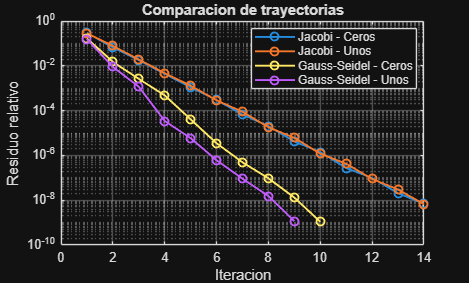

figure;

indices = [2, 5, 8, 11];

for i = 1:length(indices)

    idx = indices(i);

    semilogy(1:length(historiales{idx}), ...
        max(historiales{idx},eps), ...
        '-o', 'LineWidth',1.4);

    hold on;
end

grid on;

xlabel('Iteracion');
ylabel('Residuo relativo');

legend('Jacobi - Ceros', ...
    'Jacobi - Unos', ...
    'Gauss-Seidel - Ceros', ...
    'Gauss-Seidel - Unos', ...
    'Location','best');

title('Comparacion de trayectorias');

Al evaluar los métodos de Jacobi y Gauss–Seidel con diferentes condiciones iniciales y tolerancias, se observó convergencia en los 12 experimentos. Para una tolerancia de ${10}^{-8}$, Jacobi requirió 14 iteraciones con ambas semillas, mientras que Gauss–Seidel necesitó 10 iteraciones con la semilla de ceros y 9 con la de unos. Al reducir la tolerancia de ${10}^4$ a ${10}^{-10}$, las iteraciones de Jacobi aumentaron de 7 a 18 y las de Gauss–Seidel de 5 a 12, utilizando la semilla de ceros. Los residuos finales disminuyeron, aunque los errores no lo hicieron en una proporción exactamente igual al cambio de tolerancia. Estos resultados muestran que Gauss–Seidel presentó una convergencia más rápida para el sistema estudiado y que tanto la tolerancia como la condición inicial influyen en el comportamiento numérico de los métodos.

**4.3**

**Predicción:**

Matriz original:


$$\left\lbrack \begin{array}{cccc}6\ldotp 05 & -1 & 0 & 1\\-1 & 6\ldotp 05
 & -1 & 0\\0 & -1 & 5\ldotp 25 & -1\\1 & 0 & -1 & 5\end{array}\right\rbrack \to
 \left\lbrack \begin{array}{cccc}2 & 1 & 4 & 3\end{array}\right\rbrack \to \left\lbrack
 \begin{array}{cccc}-1 & 6\ldotp 05 & -1 & 0\\6\ldotp 05 & -1 & 0 & 1\\1 & 0
 & -1 & 5\\0 & -1 & 5\ldotp 25 & -1\end{array}\right\rbrack$$


La matriz reordenada, resulta en una diagonal no dominante, significando que los elementos fuera de la diagonal tienen magnitudes mayores, por lo tanto se espera que Jacobi y Gauss–Seidel presenten divergencia. Esta predicción se comprobará calculando los radios espectrales de sus matrices de iteración.

    Pb = eye(4);
Pb = Pb([2 1 4 3],:);

Ab = Pb*A;
bb = Pb*b;

disp('Matriz reordenada:');

Matriz reordenada:


disp(Ab);

           -1         6.05           -1            0
         6.05           -1            0            1
            1            0           -1            5
            0           -1         5.25           -1




disp('Diagonal reordenada:');

Diagonal reordenada:


disp(diag(Ab));

    -1
    -1
    -1
    -1



## Matrices de iteracion

Db = diag(diag(Ab));
Lb = tril(Ab,-1);
Ub = triu(Ab,1);

BJb = -Db\(Lb+Ub);
BGSb = -(Db+Lb)\Ub;

rhoJb = max(abs(eig(BJb)));
rhoGSb = max(abs(eig(BGSb)));

fprintf('Radio Jacobi reordenado: %.6f\n',rhoJb);

Radio Jacobi reordenado: 5.959926


fprintf('Radio GS reordenado: %.6f\n',rhoGSb);

Radio GS reordenado: 35.520714


## Comparacion de convergencia

maxIter = 500;
tol = 1e-8;
limite = 1e10;

histJb = [];
histGSb = [];

for metodo = 1:2

    x = zeros(4,1);
    historial = zeros(maxIter,1);
    estado = "Maximo de iteraciones";

    for k = 1:maxIter

        xAnterior = x;

        if metodo == 1
            x = Db\(bb-(Lb+Ub)*xAnterior);
        else
            x = (Db+Lb)\(bb-Ub*xAnterior);
        end

        Rr = norm(bb-Ab*x,inf)/norm(bb,inf);
        historial(k) = Rr;

        if ~isfinite(Rr) || Rr > limite
            estado = "Divergencia";
            break
        end

        if Rr < tol
            estado = "Convergencia";
            break
        end
    end

    historial = historial(1:k);

    if metodo == 1
        histJb = historial;
        fprintf('\nJacobi: %s, %d iteraciones\n',estado,k);
    else
        histGSb = historial;
        fprintf('Gauss-Seidel: %s, %d iteraciones\n',estado,k);
    end
end


Jacobi: Divergencia, 14 iteraciones


Gauss-Seidel: Divergencia, 7 iteraciones


## Grafica base vs reordenado

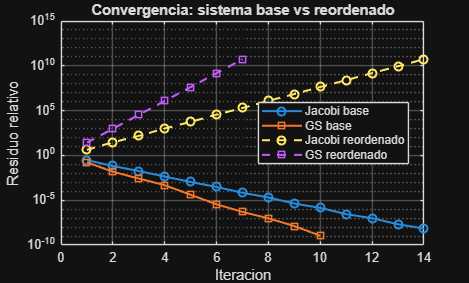

figure;

semilogy(1:length(resJ),resJ,'-o','LineWidth',1.5);
hold on;

semilogy(1:length(resGS),resGS,'-s','LineWidth',1.5);

semilogy(1:length(histJb),histJb,'--o','LineWidth',1.5);

semilogy(1:length(histGSb),histGSb,'--s','LineWidth',1.5);

grid on;

xlabel('Iteracion');
ylabel('Residuo relativo');

legend('Jacobi base','GS base', ...
       'Jacobi reordenado','GS reordenado', ...
       'Location','best');

title('Convergencia: sistema base vs reordenado');

El reordenamiento produjo radios espectrales aproximados de 5.960 para Jacobi y 35.521 para Gauss–Seidel, ambos mayores que uno, lo que confirma la divergencia esperada. En comparación, el sistema original presentó radios espectrales menores que uno y ambos métodos convergieron. Esto demuestra que el orden de las ecuaciones influye en la convergencia de los métodos iterativos, aunque no modifica la solución exacta del sistema.

Para recuperar un comportamiento favorable, se propone reordenar las filas como ([2,1,4,3]) sobre la matriz reordenada, recuperando así la matriz original y su dominancia diagonal estricta.

**4.4**

tol = 1e-8;
maxIter = 500;
x0 = zeros(4,1);

omegas = 0.6:0.1:1.8;

n = length(omegas);

iteracionesSOR = zeros(n,1);
residuosSOR = zeros(n,1);
tiemposSOR = zeros(n,1);
erroresSOR = zeros(n,1);
estadosSOR = strings(n,1);

historialesSOR = cell(n,1);

## Barrido de omega

for i = 1:n

    omega = omegas(i);
    x = x0;

    historial = zeros(maxIter,1);
    convergio = false;

    tic;

    for k = 1:maxIter

        xAnterior = x;

        % Actualizacion SOR
        x = (D+omega*L)\ ...
            (omega*b + ((1-omega)*D-omega*U)*xAnterior);

        % Residuo relativo
        Rr = norm(b-A*x,inf)/norm(b,inf);

        historial(k) = Rr;

        % Proteccion numerica
        if ~all(isfinite(x)) || ~isfinite(Rr) || Rr > 1e10
            break
        end

        % Criterio de convergencia
        if Rr < tol
            convergio = true;
            break
        end

    end

    tiemposSOR(i) = toc;

    iteracionesSOR(i) = k;
    residuosSOR(i) = Rr;
    erroresSOR(i) = norm(x-xref,inf);

    historialesSOR{i} = historial(1:k);

    if convergio
        estadosSOR(i) = "Convergió";
    else
        estadosSOR(i) = "No convergió";
    end

end

## Tabla de resultados

tablaSOR = table(omegas', iteracionesSOR, ...
    residuosSOR, tiemposSOR, erroresSOR, estadosSOR, ...
    'VariableNames', {'Omega','Iteraciones', ...
    'Residuo','Tiempo_s','Error','Estado'});

disp(tablaSOR);

    Omega    Iteraciones     Residuo      Tiempo_s       Error         Estado   
    _____    ___________    __________    _________    __________    ___________

     0.6         27         6.9132e-09    0.0022782    1.4119e-08    "Convergió"
     0.7         21         6.3832e-09     4.51e-05    1.3213e-08    "Convergió"
     0.8         17         3.6873e-09        3e-05     6.826e-09    "Convergió"
     0.9         13         2.2984e-09     2.48e-05     3.771e-09    "Convergió"
       1         10         1.0856e-09     8.61e-05     1.699e-09    "Convergió"
     1.1         11         4.4311e-09     1.83e-05    6.6315e-09    "Convergió"
     1.2         15         3.0384e-09      8.4e-06    4.5493e-09    "Convergió"
     1.3         19         4.6182e-09     1.13e-05    6.8181e-09    "Convergió"
     1.4         24         8.3271e-09     1.43e-05    1.0779e-08    "Convergió"
     1.5         32         6.0139e-09     1.92e-05    7.2102e-09    "Convergió"
     1.6         43        

## Mejor omega por iteraciones

validos = find(estadosSOR == "Convergió");

[~,posIter] = min(iteracionesSOR(validos));
idxMejorIter = validos(posIter);

omegaMejor = omegas(idxMejorIter);

## Mejor omega por tiempo

[~,posTiempo] = min(tiemposSOR(validos));
idxMejorTiempo = validos(posTiempo);

omegaMasRapido = omegas(idxMejorTiempo);

fprintf('\nMejor omega por iteraciones: %.2f\n',omegaMejor);


Mejor omega por iteraciones: 1.00


fprintf('Iteraciones: %d\n',iteracionesSOR(idxMejorIter));

Iteraciones: 10



fprintf('\nMejor omega por tiempo: %.2f\n',omegaMasRapido);


Mejor omega por tiempo: 1.20


fprintf('Tiempo: %.8e s\n',tiemposSOR(idxMejorTiempo));

Tiempo: 8.40000000e-06 s


## Verificacion SOR omega = 1 y Gauss-Seidel

xSOR1 = x0;

for k = 1:maxIter

    xAnterior = xSOR1;

    xSOR1 = (D+L)\(b-U*xAnterior);

    Rr = norm(b-A*xSOR1,inf)/norm(b,inf);

    if Rr < tol
        break
    end
end

fprintf('\nDiferencia SOR(1) vs GS: %.8e\n', ...
    norm(xSOR1-xGS,inf));


Diferencia SOR(1) vs GS: 0.00000000e+00


## Grafica 1: residuos

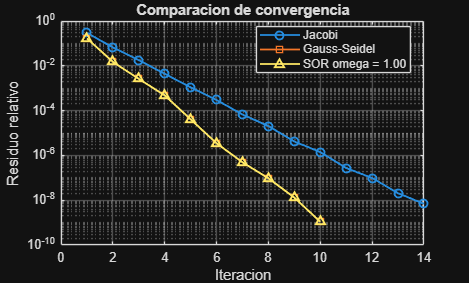

figure;

semilogy(1:length(resJ),max(resJ,eps), ...
    '-o','LineWidth',1.4);
hold on;

semilogy(1:length(resGS),max(resGS,eps), ...
    '-s','LineWidth',1.4);

histMejor = historialesSOR{idxMejorIter};

semilogy(1:length(histMejor),max(histMejor,eps), ...
    '-^','LineWidth',1.4);

grid on;

xlabel('Iteracion');
ylabel('Residuo relativo');

legend('Jacobi','Gauss-Seidel', ...
    sprintf('SOR omega = %.2f',omegaMejor), ...
    'Location','best');

title('Comparacion de convergencia');

## Grafica 2: iteraciones frente a omega

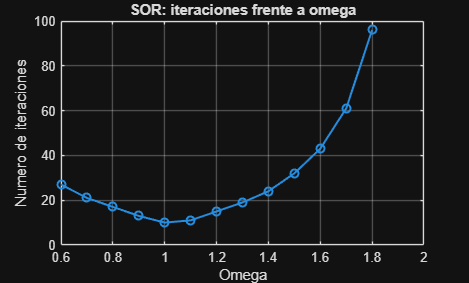

figure;

plot(omegas,iteracionesSOR,'-o','LineWidth',1.5);

grid on;

xlabel('Omega');
ylabel('Numero de iteraciones');

title('SOR: iteraciones frente a omega');

## Grafica 3: tiempo frente a omega

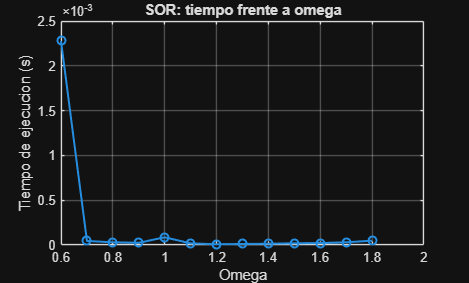

figure;

plot(omegas,tiemposSOR,'-o','LineWidth',1.5);

grid on;

xlabel('Omega');
ylabel('Tiempo de ejecucion (s)');

title('SOR: tiempo frente a omega');

Al evaluar el método SOR para valores de $\omega$ entre 0.6 y 1.8, se observó convergencia en todos los casos. El menor número de iteraciones se obtuvo con $\omega =1$, requiriendo 10 iteraciones y alcanzando un residuo relativo de $1\ldotp 0856\times 10^{-9}$. Además, se verificó que este valor reproduce exactamente la solución de Gauss–Seidel, con una diferencia numérica igual a cero.

Para valores menores que uno, las iteraciones aumentaron hasta 27 con $\omega =0\ldotp 6$, mientras que para valores superiores a uno aumentaron hasta 96 con $\omega =1\ldotp 8$. El menor tiempo registrado fue de $2\ldotp 51\times {10}^{-5} s$ para  $\omega =1\ldotp 2$, con 15 iteraciones. Sin embargo, debido a la corta duración de las ejecuciones, las mediciones de tiempo pueden presentar variaciones. Por lo tanto, se concluye que para este sistema,  $\omega =1$fue la mejor elección según el número de iteraciones, aunque no presentó el menor tiempo medido.

## Punto 5. Caso integrador de ingeniería: red lineal y elemento no lineal.

**5.1**

% Conductancias en siemens
g12 = (2 + 0.05*d7)*1e-3;
g23 = (1.5 + 0.03*d8)*1e-3;
g13 = (0.5 + 0.02*d9)*1e-3;

g10 = 1.0e-3;
g20 = 1.2e-3;

% Corriente de alimentacion en amperios
I1 = (3 + 0.1*d7)*1e-3;

% Matriz nodal
AT = [g10+g12+g13, -g12,         -g13;
    -g12,         g20+g12+g23, -g23;
    -g13,         -g23,         g13+g23];

% Vector de corrientes
iT = [I1; 0; 0];

% Solucion del sistema lineal
V = AT\iT;

V1 = V(1);
V2 = V(2);
V3 = V(3);

% Voltaje de Thevenin
Vth = V3;

fprintf('Voltaje V1 = %.8f V\n',V1);

Voltaje V1 = 1.71384300 V


fprintf('Voltaje V2 = %.8f V\n',V2);

Voltaje V2 = 1.15513084 V


fprintf('Voltaje V3 = %.8f V\n',V3);

Voltaje V3 = 1.31251454 V


fprintf('Voltaje Thevenin = %.8f V\n',Vth);

Voltaje Thevenin = 1.31251454 V


## Balance de corrientes

% Corrientes de cada rama
I12 = g12*(V1-V2);
I23 = g23*(V2-V3);
I13 = g13*(V1-V3);

I10 = g10*V1;
I20 = g20*V2;

% Balance nodal (KCL)
balance1 = I1-I12-I13-I10;
balance2 = I12-I23-I20;
balance3 = I13+I23;

% Tabla de comprobacion
tablaBalance = table((1:3)', ...
    [balance1;balance2;balance3], ...
    abs([balance1;balance2;balance3]), ...
    'VariableNames', ...
    {'Nodo','Balance_A','ErrorAbsoluto_A'});

disp(tablaBalance);

    Nodo     Balance_A     ErrorAbsoluto_A
    ____    ___________    _______________

     1      -2.1684e-19      2.1684e-19   
     2       8.6736e-19      8.6736e-19   
     3      -5.9631e-19      5.9631e-19   



% Residuo del sistema
residuo = norm(iT-AT*V,inf);

fprintf('\nResiduo del sistema = %.8e A\n',residuo);


Residuo del sistema = 1.30104261e-18 A


Al resolver el sistema nodal se obtuvieron voltajes de 1.713843 V, 1.155131 V y 1.312515 V para los nodos 1, 2 y 3, respectivamente. Como el puerto del diodo permanece abierto, el voltaje del nodo 3 corresponde al voltaje de Thévenin de la red. El balance de corrientes presentó diferencias del orden de ${10}^{-19} \;A$, lo que confirma el cumplimiento de la ley de Kirchhoff dentro de la precisión numérica. Por lo tanto, el sistema lineal permite determinar de manera consistente el comportamiento de la red resistiva.

**5.2**

% Desactivar fuente independiente
Iprueba = 1e-3;
% Aplicar corriente de prueba en nodo 3
iPrueba = [0; 0; Iprueba];

% Resolver sistema lineal
Vprueba = AT\iPrueba;

V3prueba = Vprueba(3);

% Resistencia de Thevenin
Rth = V3prueba/Iprueba;

fprintf('Voltaje de prueba V1 = %.8f V\n',Vprueba(1));

Voltaje de prueba V1 = 0.42339179 V


fprintf('Voltaje de prueba V2 = %.8f V\n',Vprueba(2));

Voltaje de prueba V2 = 0.48050684 V


fprintf('Voltaje de prueba V3 = %.8f V\n',V3prueba);

Voltaje de prueba V3 = 0.93390166 V



fprintf('\nResistencia de Thevenin = %.8f Ohm\n',Rth);


Resistencia de Thevenin = 933.90166339 Ohm



% Comprobacion
residuoPrueba = norm(iPrueba-AT*Vprueba,inf);

fprintf('Residuo del sistema = %.8e A\n',residuoPrueba);

Residuo del sistema = 0.00000000e+00 A


Al desactivar la fuente independiente y aplicar una corriente de prueba de 1 mA en el nodo 3, se obtuvo un voltaje de 0.93390166 V, correspondiente a una resistencia de Thévenin de 933.90166 Ω. El residuo del sistema fue cero a la precisión mostrada, lo que confirma la consistencia numérica de la solución. Tanto el cálculo del voltaje de Thévenin como el de la resistencia equivalente se realizaron mediante sistemas lineales, ya que las conductancias permanecieron constantes y únicamente cambió el vector de corrientes.

**5.3**

Is = 1e-12;
n = 1.8;
VT = 0.02585;

F = @(VD) Vth - VD - Rth*Is*expm1(VD/(n*VT));

dF = @(VD) -1 - (Rth*Is/(n*VT))*exp(VD/(n*VT));

tol = 1e-10;
maxIter = 100;

## Grafica: recta de carga y diodo

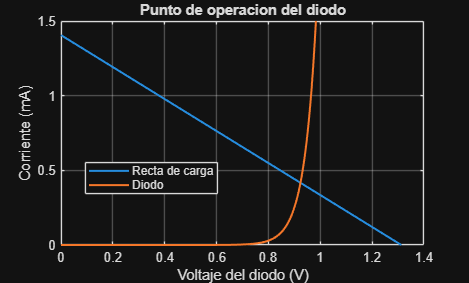

VDgraf = linspace(0,Vth,1000);

Icarga = (Vth-VDgraf)/Rth;
Idiodo = Is*expm1(VDgraf/(n*VT));

figure;
plot(VDgraf,Icarga*1e3,'LineWidth',1.5);
hold on;
plot(VDgraf,Idiodo*1e3,'LineWidth',1.5);
grid on;

xlabel('Voltaje del diodo (V)');
ylabel('Corriente (mA)');
legend('Recta de carga','Diodo','Location','best');
title('Punto de operacion del diodo');
ylim([0 1.5]);

## Biseccion

a = 0;
b = Vth;

if F(a)*F(b) >= 0
    error('El intervalo no presenta cambio de signo');
end

for kB = 1:maxIter

    VD_B = (a+b)/2;

    if abs(F(VD_B)) < tol || (b-a)/2 < tol
        break
    end

    if F(a)*F(VD_B) < 0
        b = VD_B;
    else
        a = VD_B;
    end
end

resB = abs(F(VD_B));

## Newton-Raphson

VD_N = 0.9;

for kN = 1:maxIter

    VDnuevo = VD_N - F(VD_N)/dF(VD_N);

    if ~isfinite(VDnuevo)
        error('Newton produjo un valor no finito');
    end

    VD_N = VDnuevo;

    if abs(F(VD_N)) < tol
        break
    end
end

resN = abs(F(VD_N));

## Comparacion

tabla53 = table( ...
    ["Biseccion";"Newton-Raphson"], ...
    [VD_B;VD_N], ...
    [resB;resN], ...
    [kB;kN], ...
    'VariableNames', ...
    {'Metodo','Voltaje_V','Residuo_V','Iteraciones'});

disp(tabla53);

         Metodo         Voltaje_V    Residuo_V     Iteraciones
    ________________    _________    __________    ___________

    "Biseccion"          0.9235      8.1427e-11        34     
    "Newton-Raphson"     0.9235      9.2203e-11         4     



## Sensibilidad a la semilla de Newton

semillasN = [0.5 0.7 0.9 1.1 1.3];

iterN = zeros(length(semillasN),1);
raizN = zeros(length(semillasN),1);
resNuevos = zeros(length(semillasN),1);
estadoN = strings(length(semillasN),1);

for j = 1:length(semillasN)

    x = semillasN(j);
    convergio = false;

    for k = 1:maxIter

        % Evaluacion segura
        if ~isfinite(F(x)) || ~isfinite(dF(x)) || ...
                abs(dF(x)) < 1e-14
            break
        end

        xNuevo = x - F(x)/dF(x);

        if ~isfinite(xNuevo)
            break
        end

        x = xNuevo;

        if abs(F(x)) < tol
            convergio = true;
            break
        end
    end

    iterN(j) = k;
    raizN(j) = x;
    resNuevos(j) = abs(F(x));

    if convergio
        estadoN(j) = "Convergió";
    else
        estadoN(j) = "No convergió";
    end
end

tablaSensibilidad = table(semillasN',raizN, ...
    resNuevos,iterN,estadoN, ...
    'VariableNames', ...
    {'Semilla','Raiz','Residuo','Iteraciones','Estado'});

disp(tablaSensibilidad);

    Semilla     Raiz      Residuo      Iteraciones      Estado   
    _______    ______    __________    ___________    ___________

      0.5      0.9235    7.2164e-16        14         "Convergió"
      0.7      0.9235    7.2164e-16        13         "Convergió"
      0.9      0.9235    9.2203e-11         4         "Convergió"
      1.1      0.9235     5.651e-14         8         "Convergió"
      1.3      0.9235    1.8682e-11        12         "Convergió"



**5.4**

VD = VD_N;

% Corriente Thevenin
ID = (Vth-VD)/Rth;

% Corriente Shockley
ID_Shockley = Is*expm1(VD/(n*VT));

% Potencia del diodo
PD = VD*ID;

% Diferencia entre corrientes
diferenciaI = abs(ID-ID_Shockley);

errorRelI = diferenciaI/max(abs(ID_Shockley),eps)*100;

fprintf('Voltaje del diodo = %.8f V\n',VD);

Voltaje del diodo = 0.92350420 V


fprintf('Corriente Thevenin = %.8e A\n',ID);

Corriente Thevenin = 4.16543149e-04 A


fprintf('Corriente Shockley = %.8e A\n',ID_Shockley);

Corriente Shockley = 4.16543149e-04 A


fprintf('Potencia del diodo = %.8e W\n',PD);

Potencia del diodo = 3.84679349e-04 W



fprintf('\nDiferencia entre corrientes = %.8e A\n',diferenciaI);


Diferencia entre corrientes = 9.87285340e-14 A


fprintf('Error relativo entre corrientes = %.8e %%\n',errorRelI);

Error relativo entre corrientes = 2.37018744e-08 %


%g12=+5%

g12_n = 1.05*g12;

% Nueva matriz nodal
AT_n = [g10+g12_n+g13, -g12_n,         -g13;
            -g12_n,         g20+g12_n+g23, -g23;
            -g13,               -g23,              g13+g23];

## Nuevo voltaje de Thevenin

V_n = AT_n\iT;

Vth_n = V_n(3);

## Nueva resistencia de Thevenin

Vprueba_n = AT_n\iPrueba;

Rth_n = Vprueba_n(3)/Iprueba;

## Nuevo punto de operacion del diodo

F_nueva = @(VD) Vth_n - VD - ...
    Rth_n*Is*expm1(VD/(n*VT));

% Metodo cerrado: biseccion
a = 0;
b = Vth_n;

tol = 1e-10;
maxIter = 100;

if F_nueva(a)*F_nueva(b) >= 0
    error('Intervalo invalido para biseccion');
end

for k = 1:maxIter

    VD_n = (a+b)/2;

    if abs(F_nueva(VD_n)) < tol || ...
            (b-a)/2 < tol
        break
    end

    if F_nueva(a)*F_nueva(VD_n) < 0
        b = VD_n;
    else
        a = VD_n;
    end
end

## Nueva corriente y potencia

ID_n = (Vth_n-VD_n)/Rth_n;

ID_Shockley_n = Is*expm1(VD_n/(n*VT));

PD_n = VD_n*ID_n;

## Cambios relativos porcentuales

cambioVth = (Vth_n-Vth)/abs(Vth)*100;
cambioRth = (Rth_n-Rth)/abs(Rth)*100;
cambioVD = (VD_n-VD)/abs(VD)*100;
cambioID = (ID_n-ID)/abs(ID)*100;

## Tabla comparativa

Parametro = ["Vth (V)";
             "Rth (Ohm)";
             "VD (V)";
             "ID (mA)"];

Original = [Vth;
            Rth;
            VD;
            ID*1e3];

Perturbado = [Vth_n;
              Rth_n;
              VD_n;
              ID_n*1e3];

CambioRelativo_pct = [cambioVth;
                      cambioRth;
                      cambioVD;
                      cambioID];

tabla54 = table(Parametro,Original,Perturbado, ...
    CambioRelativo_pct);

disp(tabla54);

     Parametro     Original    Perturbado    CambioRelativo_pct
    ___________    ________    __________    __________________

    "Vth (V)"       1.3125       1.3157            0.24104     
    "Rth (Ohm)"      933.9       933.58           -0.03463     
    "VD (V)"        0.9235      0.92386            0.03804     
    "ID (mA)"      0.41654       0.4197            0.75786     



## Comprobacion del nuevo punto de operacion

fprintf('\nResiduo nuevo = %.8e V\n',abs(F_nueva(VD_n)));


Residuo nuevo = 5.11758524e-10 V


fprintf('Diferencia entre corrientes = %.8e A\n', ...
    abs(ID_n-ID_Shockley_n));

Diferencia entre corrientes = 5.48168824e-13 A


fprintf('Potencia nueva = %.8e W\n',PD_n);

Potencia nueva = 3.87742118e-04 W


Los métodos de bisección y Newton–Raphson convergieron al mismo punto de operación del diodo, con un voltaje aproximado de 0.9235 V. Sin embargo, bisección requirió 34 iteraciones, mientras que Newton–Raphson necesitó únicamente 4, evidenciando una convergencia más rápida de este último para la semilla seleccionada. Al evaluar la sensibilidad de Newton–Raphson con cinco semillas entre 0.5 V y 1.3 V, todas convergieron a la misma raíz, aunque el número de iteraciones varió entre 4 y 14. Esto demuestra que la elección de la semilla influye en la rapidez de convergencia, mientras que bisección ofrece mayor garantía de convergencia cuando se dispone de un intervalo válido con cambio de signo.

La corriente del diodo calculada mediante el equivalente de Thévenin fue aproximadamente 0.41654 mA, consistente con la obtenida mediante la ecuación de Shockley. A partir del voltaje y la corriente se obtiene una potencia disipada cercana a $0\ldotp 385\times {10}^{-3} \;W$, lo que confirma un comportamiento físicamente consistente del punto de operación.

Finalmente, la perturbación modificó ligeramente los parámetros del equivalente lineal de Thévenin, pero su efecto sobre el punto de operación no fue uniforme. Aunque el voltaje del diodo presentó una variación pequeña, la corriente mostró una mayor sensibilidad dada la relación exponencial de Shockley. Esto evidencia que la etapa no lineal puede amplificar pequeñas variaciones de las condiciones eléctricas de alimentación.

**Análisis requerido:**

El cálculo del equivalente de Thévenin corresponde a un problema lineal, ya que la red está formada por conductancias constantes y sus ecuaciones nodales pueden expresarse mediante el sistema (A_TV=i). Por esta razón, tanto el voltaje como la resistencia de Thévenin se obtienen resolviendo sistemas de ecuaciones lineales. En cambio, al conectar el diodo aparece la relación exponencial entre corriente y voltaje descrita por la ecuación de Shockley, lo que obliga a resolver una ecuación no lineal mediante métodos numéricos como bisección o Newton–Raphson.

Al incrementar la conductancia $g_{12}$ un 5 %, el voltaje de Thévenin aumentó un 0.24104 %, mientras que la resistencia de Thévenin disminuyó un 0.03463 %. Como consecuencia, el voltaje del diodo aumentó un 0.03804 % y su corriente un 0.75786 %. La corriente presentó la mayor variación relativa, mientras que el voltaje del diodo fue el menos afectado. Esto se explica por la característica exponencial del diodo, donde pequeñas variaciones de voltaje pueden producir cambios mayores en la corriente.

Estos resultados indican que la corriente del diodo fue la variable más sensible a la perturbación. Aunque el voltaje del diodo cambió muy poco, la dependencia exponencial de la corriente respecto al voltaje produjo una variación relativa considerablemente mayor. Por tanto, para este circuito y esta perturbación, el mayor efecto relativo se observó en la corriente de la etapa no lineal, mientras que los parámetros del equivalente de Thévenin presentaron cambios menores. Esto demuestra que una perturbación pequeña en la red lineal puede producir una respuesta proporcionalmente mayor en una variable de la etapa no lineal.

## Sexto punto. Síntesis del repaso y toma de decisiones

## 6.1 Tabla diagnóstica actualizada

itNdiodo = tablaSensibilidad.Iteraciones;
Metodo = ["Bisección"; "Falsa posición"; "Punto fijo"; "Newton-Raphson"; "Secante"; ...
    "Gauss simple"; "Gauss con pivoteo parcial"; "Pivoteo parcial escalonado"; "LU con pivoteo (PA = LU)"; ...
    "Jacobi"; "Gauss-Seidel"; "SOR"];
TipoProblema = [repmat("No lineal f(x) = 0", 5, 1); repmat("Lineal Ax = b (directo)", 4, 1); ...
    repmat("Lineal Ax = b (iterativo)", 3, 1)];
InfoInicial = ["Intervalo [a,b] con f(a)f(b) < 0"; "Intervalo [a,b] con f(a)f(b) < 0"; ...
    "Reformulación x = g(x) y semilla x0"; "Semilla x0 y derivada f'"; "Dos semillas x0, x1"; ...
    "A, b con pivotes no nulos"; "A, b"; "A, b y escalas de fila s_i"; "A y varios vectores b"; ...
    "A, b, x0, tol"; "A, b, x0, tol"; "A, b, x0, tol y omega"];
Convergencia = ["Garantizada: f continua y cambio de signo"; "Garantizada: f continua y cambio de signo"; ...
    "|g'| < 1 cerca de x* y g(I) contenido en I"; "Local cuadrática si f'(x*) ~= 0 y x0 cercano"; ...
    "Local superlineal si x0, x1 cercanos"; "Finita si todos los pivotes son no nulos"; ...
    "Finita si A es no singular"; "Finita si A es no singular"; "Finita si A es no singular"; ...
    "rho(B_J) < 1"; "rho(B_GS) < 1"; "rho(B_SOR) < 1 (exige 0 < omega < 2)"];
MetricaExito = [repmat("Ea <= tolx, |f| <= tolf y raíz buscada", 5, 1); ...
    repmat("Rr pequeño y Er coherente con kappa(A)", 3, 1); "||PA - LU||/||A|| ~ eps y Rr pequeño"; ...
    repmat("Rr < tol, estado y rho(B) < 1", 3, 1)];
CostoObservado = [ ...
    sprintf("%d it., %d evals de f; diodo: %d it.", oBis.iter, oBis.nevalf, kB); ...
    sprintf("%d it., %d evals de f (extremo b fijo)", oFP.iter, oFP.nevalf); ...
    sprintf("g1: %d it., razón %.2f", oG1.iter, razEst(3)); ...
    sprintf("%d it., %d f + %d f' (x0 = 2.5); diodo: %d it.", oN{1}.iter, oN{1}.nevalf, oN{1}.nevaldf, kN); ...
    sprintf("%d it., %d evals de f (par A)", oSA.iter, oSA.nevalf); ...
    sprintf("%d operaciones (n = 4); MaxMult = %.3f", opsGauss, T32.MaxMult(1)); ...
    sprintf("%d operaciones + búsqueda de pivote; %d intercambio(s) con P0A", opsGauss, T32P0.Intercambios(2)); ...
    sprintf("%d operaciones + escalas; %d intercambios en As", opsGauss, T33.Intercambios(3)); ...
    sprintf("%d (factorización) + %d por vector; %d vs %d para %d vectores", opsFact, opsSust, ...
        opsFact + nB*opsSust, nB*opsGauss, nB); ...
    sprintf("%d it. (tol = 1e-8), rho = %.3f", kJ, rhoJ); ...
    sprintf("%d it. (tol = 1e-8), rho = %.3f", kGS, rhoGS); ...
    sprintf("omega = %.1f: %d it.; omega = %.1f: %d it.", omegaMejor, iteracionesSOR(idxMejorIter), ...
        omegas(end), iteracionesSOR(end))];
Sensibilidad = [ ...
    sprintf("Baja; con 1/x en [-1,2] termina en un polo (|f| = %.0e, %s)", o12d.residuo, o12d.estado); ...
    sprintf("Curvatura: razón %.2f, no mejor que bisección (%.2f)", razEst(2), razEst(1)); ...
    sprintf("Reformulación: |g1'(x*)| = %.2f converge, |g2'(x*)| = %.2f diverge en %d it.", ...
        dg1(rRef), dg2(rRef), oG2.iter); ...
    sprintf("Alta: x0 = 1.16 -> raíz %s, x0 = 1.15 -> raíz %s; diodo: %d a %d it.", ...
        T2.RaizAlcanzada(6), T2.RaizAlcanzada(7), min(itNdiodo), max(itNdiodo)); ...
    sprintf("Par B salta a x = %.0f y usa %d it. (par A: %d)", oSB.hist.("x_{n+1}")(1), oSB.iter, oSA.iter); ...
    sprintf("Orden de filas: con P0A falla en el paso %d", infoGS0.pasoFalla); ...
    sprintf("Escala de filas: Er = %.1e en As frente a %.1e en A", T33.Er(2), T32.Er(2)); ...
    sprintf("Invariante a la escala de filas: Er = %.1e en A y en As", T33.Er(3)); ...
    sprintf("Idéntica a Gauss con pivoteo: ||xLU - xGauss|| = %.1e", max(T34.("||xLU-xGauss||"))); ...
    sprintf("Orden de filas: rho = %.2f al reordenar (diverge)", rhoJb); ...
    sprintf("Orden de filas: rho = %.2f al reordenar (diverge en %d it.)", rhoGSb, numel(histGSb)); ...
    sprintf("omega: de %d a %d it. en [%.1f, %.1f]", min(iteracionesSOR), max(iteracionesSOR), omegas(1), omegas(end))];
FallaTipica = ["Intervalo sin cambio de signo o discontinuidad"; "Extremo estancado: convergencia lenta"; ...
    "|g'(x*)| >= 1: divergencia"; "f' ~ 0: salto lejano, derivada_pequena u otra raíz"; ...
    "Secante casi horizontal: paso pequeño sin convergencia"; "Pivote nulo o pequeño"; ...
    "No corrige escalamiento ni condicionamiento"; "No corrige el mal condicionamiento"; ...
    "Pivote nulo en la factorización (A singular)"; "rho(B_J) >= 1: divergencia"; ...
    "rho(B_GS) >= 1: divergencia"; "omega mal elegido: lentitud o divergencia"];
T6 = table(Metodo, TipoProblema, InfoInicial, Convergencia, MetricaExito, CostoObservado, ...
    Sensibilidad, FallaTipica)

T6 = 12×8 table
               Metodo                      TipoProblema                         InfoInicial                                  Convergencia                                   MetricaExito                                           CostoObservado                                                               Sensibilidad                                                             FallaTipica                       
    ____________________________    ___________________________    _____________________________________    ______________________________________________    ________________________________________    ________________________________________________________________    _________________________________________________________________________________    ________________________________________________________

    "Bisección"                     "No lineal f(x) = 0"           "Intervalo [a,b] con f(a)f(b) < 0"       "Garantizada: f continua y cambio de signo"       "

## Tabla del punto 1 con la evidencia obtenida

T1.Evidencia(1) = sprintf(['kappa(A) = %.2f, rho_GS = %.3f. Pivoteo parcial: Rr = %.1e, Er = %.1e; ' ...
    'Gauss simple falla en el paso %d con P0A; ||PA - LU||/||A|| = %.1e'], ...
    kappaA, rhoGS, T32.Rr(2), T32.Er(2), infoGS0.pasoFalla, errLU);
T1.Evidencia(3) = sprintf(['Vth = %.4f V, Rth = %.2f Ohm. VD = %.4f V: bisección %d it. (|F| = %.1e), ' ...
    'Newton %d it. (|F| = %.1e); |ID - ID_Shockley| = %.1e A'], ...
    Vth, Rth, VD_N, kB, resB, kN, resN, diferenciaI);
T1.Evidencia(4) = sprintf(['Equivalente al punto 5: etapa lineal (AT V = i, residuo %.1e A) seguida de ' ...
    'etapa no lineal F(VD) = 0; +5 %% en g12 cambia Vth %.2f %% e ID %.2f %%'], residuo, cambioVth, cambioID);
T1

T1 = 4×7 table
        Situacion                        Tipo                                          DatosIniciales                                             CriterioExito                                            SenalFalla                                   MetodoInicial                                                                                     Evidencia                                                                        
    __________________    ___________________________________    ___________________________________________________________    _________________________________________________    _______________________________________________________    ______________________________    _________________________________________________________________________________________________________________________________________________________

    "a. Ax = b"           "Lineal"                               "A y b; no singularidad, kappa(A) y estructura"                

## 6.2 Recomendaciones por escenario

Escenario = ["I. Solo un intervalo con cambio de signo"; ...
    "II. Buena semilla y derivada confiable"; ...
    "III. Pivote inicial nulo"; ...
    "IV. Sistema mal escalado"; ...
    "V. Matriz favorable para iterativos, resolución repetida"; ...
    "VI. Valores finitos pero solución poco confiable"];
Recomendacion = string({ ...
    sprintf(['Bisección (garantía con f continua): en [1,3] convergió en %d it. con |f| = %.1e y en el ' ...
    'diodo en %d it. sobre [0, Vth]. Falsa posición no es siempre más rápida (%d it., extremo fijo). ' ...
    'Refinar después con Newton.'], oBis.iter, oBis.residuo, kB, oFP.iter); ...
    sprintf(['Newton vigilando |f''| y la raíz alcanzada: %d it. desde x0 = 2.5 (orden %.2f) y %d it. en el ' ...
    'diodo desde 0.9 V; pero en x0 = 2/sqrt(3) |f''| = %.1e (derivada_pequena) y desde 1.15 llegó a la ' ...
    'raíz %s.'], oN{1}.iter, pEst(4), kN, abs(df(2/sqrt(3))), T2.RaizAlcanzada(7)); ...
    sprintf(['Pivoteo parcial: con P0A Gauss simple termina en %s en el paso %d; el pivoteo parcial ' ...
    'resuelve con %d intercambio(s), Rr = %.1e y Er = %.1e.'], T32P0.Estado(1), T32P0.PasoFalla(1), ...
    T32P0.Intercambios(2), T32P0.Rr(2), T32P0.Er(2)); ...
    sprintf(['Pivoteo escalonado o reescalar filas: con S, kappa pasa de %.2f a %.1e; el pivoteo parcial ' ...
    'hizo %d intercambios y Er = %.1e, el escalonado Er = %.1e. Evaluar con el error o con el residuo ' ...
    'del sistema original: Er/Rr llegó a %.1e.'], kappaA3, kappaAs, T33.Intercambios(2), T33.Er(2), ...
    T33.Er(3), max(T33.Er./T33.Rr)); ...
    sprintf(['Comprobar rho(B) < 1 y usar Gauss-Seidel o SOR (rho_GS = %.3f, %d it.; SOR con omega = %.1f, ' ...
    '%d it.), conservando un orden de filas favorable (reordenado: rho_GS = %.1f, diverge). Si A es pequeña ' ...
    'y fija, factorizar una vez: %d frente a %d operaciones para %d vectores.'], rhoGS, kGS, omegaMejor, ...
    iteracionesSOR(idxMejorIter), rhoGSb, opsFact + nB*opsSust, nB*opsGauss, nB); ...
    sprintf(['Contrastar estado, residuo, error y kappa: en 1.2a Rr = %.0e con Er = %.0f; Newton desde 1.15 ' ...
    'terminó en convergio con |f| = %.1e pero en la raíz %s; la secante B tuvo Ea = %.1e con |f| = %.2f. ' ...
    'Verificar coherencia física: balance KCL %.1e A y |ID - ID_Shockley| = %.1e A.'], Rr12a, Er12a, ...
    oN{3}.residuo, T2.RaizAlcanzada(7), EaMin, oSB.hist.("r_{n+1}")(lejos(kMin)), ...
    max(tablaBalance.ErrorAbsoluto_A), diferenciaI)});
T62 = table(Escenario, Recomendacion);
for i = 1:height(T62)
    fprintf('%s\n    %s\n\n', T62.Escenario(i), T62.Recomendacion(i));
end

I. Solo un intervalo con cambio de signo
    Bisección (garantía con f continua): en [1,3] convergió en 28 it. con |f| = 2.4e-10 y en el diodo en 34 it. sobre [0, Vth]. Falsa posición no es siempre más rápida (32 it., extremo fijo). Refinar después con Newton.

II. Buena semilla y derivada confiable
    Newton vigilando |f'| y la raíz alcanzada: 6 it. desde x0 = 2.5 (orden 1.94) y 4 it. en el diodo desde 0.9 V; pero en x0 = 2/sqrt(3) |f'| = 8.9e-16 (derivada_pequena) y desde 1.15 llegó a la raíz negativa.

III. Pivote inicial nulo
    Pivoteo parcial: con P0A Gauss simple termina en pivote_nulo en el paso 1; el pivoteo parcial resuelve con 1 intercambio(s), Rr = 1.9e-16 y Er = 6.4e-17.

IV. Sistema mal escalado
    Pivoteo escalonado o reescalar filas: con S, kappa pasa de 1.93 a 9.9e+09; el pivoteo parcial hizo 3 intercambios y Er = 2.8e-15, el escalonado Er = 6.4e-17. Evaluar con el error o con el residuo del sistema original: Er/Rr llegó a 4.4e+04.

V. Matriz favorable para iterativ

## 6.3 Señales de un resultado numérico confiable

fprintf(['1. El estado de salida es necesario pero no suficiente: Newton desde 1.15 reportó convergio ' ...
    'en la raíz %s.\n'], T2.RaizAlcanzada(7));

1. El estado de salida es necesario pero no suficiente: Newton desde 1.15 reportó convergio en la raíz negativa.


fprintf(['2. El residuo se interpreta con el condicionamiento: en 1.2a Rr = %.0e con Er = %.0f, y en As ' ...
    'Er/Rr llegó a %.0e (kappa(As) = %.0e).\n'], Rr12a, Er12a, max(T33.Er./T33.Rr), kappaAs);

2. El residuo se interpreta con el condicionamiento: en 1.2a Rr = 5e-11 con Er = 1, y en As Er/Rr llegó a 4e+04 (kappa(As) = 1e+10).


fprintf(['3. El paso pequeño no basta: la secante B tuvo Ea = %.0e con |f| = %.2f; el criterio doble ' ...
    'evitó una convergencia falsa.\n'], EaMin, oSB.hist.("r_{n+1}")(lejos(kMin)));

3. El paso pequeño no basta: la secante B tuvo Ea = 4e-05 con |f| = 2.45; el criterio doble evitó una convergencia falsa.


fprintf(['4. El historial confirma el régimen: razones constantes (FP %.2f, g1 %.2f), orden %.2f en ' ...
    'Newton; g2 creció hasta %.0e.\n'], razEst(2), razEst(3), pEst(4), oG2.raiz);

4. El historial confirma el régimen: razones constantes (FP 0.52, g1 0.36), orden 1.94 en Newton; g2 creció hasta 4e+09.


fprintf(['5. El radio espectral anticipa el iterativo: rho_J = %.2f y rho_GS = %.2f convergen; al ' ...
    'reordenar, rho_GS = %.1f diverge.\n'], rhoJ, rhoGS, rhoGSb);

5. El radio espectral anticipa el iterativo: rho_J = 0.27 y rho_GS = 0.12 convergen; al reordenar, rho_GS = 35.5 diverge.


fprintf(['6. Los datos iniciales importan: mover x0 de 1.16 a 1.15 cambió la raíz; la bisección solo ' ...
    'exigió un cambio de signo.\n']);

6. Los datos iniciales importan: mover x0 de 1.16 a 1.15 cambió la raíz; la bisección solo exigió un cambio de signo.


fprintf(['7. Tolerancia: en Jacobi, tol de 1e-8 a 1e-10 llevó el error de %.1e a %.1e (factor %.0f) ' ...
    'con %d -> %d it.\n'], tabla42.errorAbsoluto(2), tabla42.errorAbsoluto(3), ...
    tabla42.errorAbsoluto(2)/tabla42.errorAbsoluto(3), tabla42.iteraciones(2), tabla42.iteraciones(3));

7. Tolerancia: en Jacobi, tol de 1e-8 a 1e-10 llevó el error de 1.3e-08 a 6.4e-11 (factor 198) con 14 -> 18 it.


fprintf(['8. Coherencia física: KCL con error %.0e A, ID de Thévenin igual a ID de Shockley ' ...
    '(diferencia %.0e A) y 0 < VD = %.4f V < Vth = %.4f V.\n'], max(tablaBalance.ErrorAbsoluto_A), ...
    diferenciaI, VD_N, Vth);

8. Coherencia física: KCL con error 9e-19 A, ID de Thévenin igual a ID de Shockley (diferencia 1e-13 A) y 0 < VD = 0.9235 V < Vth = 1.3125 V.


fprintf(['9. Sensibilidad: +5 %% en g12 cambió Vth %.2f %% pero ID %.2f %%; la etapa no lineal ' ...
    'amplifica la perturbación.\n'], cambioVth, cambioID);

9. Sensibilidad: +5 % en g12 cambió Vth 0.24 % pero ID 0.76 %; la etapa no lineal amplifica la perturbación.


fprintf(['10. Es confiable el resultado que pasa varias pruebas independientes a la vez (estado, residuo, ' ...
    'error, historial, kappa y física).\n']);

10. Es confiable el resultado que pasa varias pruebas independientes a la vez (estado, residuo, error, historial, kappa y física).


## Referencias

referencias = ["[1] R. L. Burden, J. D. Faires y A. M. Burden, Numerical Analysis, 10th ed., Cengage Learning, 2016."; ...
    "[2] S. C. Chapra y R. P. Canale, Numerical Methods for Engineers, 8th ed., McGraw-Hill, 2020."; ...
    "[3] Y. Saad, Iterative Methods for Sparse Linear Systems, 2nd ed., SIAM, 2003."; ...
    "[4] N. J. Higham, Accuracy and Stability of Numerical Algorithms, 2nd ed., SIAM, 2002."; ...
    "[5] The MathWorks, Inc., documentación de fzero, cond, rcond, lu, table, Live Editor y semilogy."];
fprintf('%s\n', referencias);

[1] R. L. Burden, J. D. Faires y A. M. Burden, Numerical Analysis, 10th ed., Cengage Learning, 2016.
[2] S. C. Chapra y R. P. Canale, Numerical Methods for Engineers, 8th ed., McGraw-Hill, 2020.
[3] Y. Saad, Iterative Methods for Sparse Linear Systems, 2nd ed., SIAM, 2003.
[4] N. J. Higham, Accuracy and Stability of Numerical Algorithms, 2nd ed., SIAM, 2002.
[5] The MathWorks, Inc., documentación de fzero, cond, rcond, lu, table, Live Editor y semilogy.


## Funciones locales

function out = biseccion(f, a, b, tolx, tolf, maxit)
% BISECCION  Método de bisección con criterio de parada doble (paso y residuo).
%   out = biseccion(f, a, b, tolx, tolf, maxit) busca una raíz de f en [a, b].
%   Declara "convergio" si |x_n - x_{n-1}| <= tolx y |f(x_n)| <= tolf.
%   Estados: "convergio", "intervalo_invalido", "max_iter".
%
%   Correcciones respecto a la versión de laboratorios anteriores:
%   - el test de signo usa sign(fa)*sign(fx) en vez de fa*fx (evita underflow/overflow);
%   - el punto medio se calcula como a + (b - a)/2;
%   - se reutilizan f(a), f(b) y se cuentan exactamente las evaluaciones de f;
%   - se exige paso Y residuo pequeños (un paso pequeño no implica convergencia).
fa = f(a); fb = f(b); nf = 2;
out = iniciarSalida(nf);
nombres = ["n","a","b","x","f(x)","Ea","Er"];
if ~(isfinite(fa) && isfinite(fb)) || sign(fa)*sign(fb) > 0
    out.estado = "intervalo_invalido"; return
end
if fa == 0 || fb == 0                       % un extremo ya es raíz
    xr = a; if fb == 0, xr = b; end
    out = cerrarSalida(out, zeros(0, 7), xr, 0, 0, 0, nf, nombres);
    out.estado = "convergio"; return
end
H = nan(maxit, 7); xold = NaN;
for n = 1:maxit
    x = a + (b - a)/2;
    fx = f(x); nf = nf + 1;
    Ea = abs(x - xold); Er = Ea/max(abs(x), eps);
    H(n,:) = [n a b x fx Ea Er];
    if sign(fa)*sign(fx) < 0
        b = x;
    else
        a = x; fa = fx;
    end
    if fx == 0 || (Ea <= tolx && abs(fx) <= tolf)
        out.estado = "convergio"; break
    end
    xold = x;
end
out = cerrarSalida(out, H(1:n,:), x, fx, Ea, n, nf, nombres);
end

function out = falsaPosicion(f, a, b, tolx, tolf, maxit)
% FALSAPOSICION  Regula falsi con criterio de parada doble (paso y residuo).
%   out = falsaPosicion(f, a, b, tolx, tolf, maxit) busca una raíz de f en [a, b].
%   Estados: "convergio", "intervalo_invalido", "max_iter".
%
%   Correcciones respecto a la versión de laboratorios anteriores:
%   - test de signo con sign() y reutilización de f en los extremos;
%   - el historial guarda a y b para poder detectar un extremo que queda fijo;
%   - se exige paso Y residuo pequeños.
fa = f(a); fb = f(b); nf = 2;
out = iniciarSalida(nf);
nombres = ["n","a","b","x","f(x)","Ea","Er"];
if ~(isfinite(fa) && isfinite(fb)) || sign(fa)*sign(fb) > 0
    out.estado = "intervalo_invalido"; return
end
if fa == 0 || fb == 0                       % un extremo ya es raíz
    xr = a; if fb == 0, xr = b; end
    out = cerrarSalida(out, zeros(0, 7), xr, 0, 0, 0, nf, nombres);
    out.estado = "convergio"; return
end
H = nan(maxit, 7); xold = NaN;
for n = 1:maxit
    x = b - fb*(b - a)/(fb - fa);
    fx = f(x); nf = nf + 1;
    Ea = abs(x - xold); Er = Ea/max(abs(x), eps);
    H(n,:) = [n a b x fx Ea Er];
    if sign(fa)*sign(fx) < 0
        b = x; fb = fx;
    else
        a = x; fa = fx;
    end
    if fx == 0 || (Ea <= tolx && abs(fx) <= tolf)
        out.estado = "convergio"; break
    end
    xold = x;
end
out = cerrarSalida(out, H(1:n,:), x, fx, Ea, n, nf, nombres);
end

function out = puntoFijo(g, f, x0, tolx, tolf, maxit)
% PUNTOFIJO  Iteración de punto fijo x_{n+1} = g(x_n).
%   out = puntoFijo(g, f, x0, tolx, tolf, maxit) vigila el paso |x_{n+1} - x_n| y el
%   residuo |f(x_{n+1})| de la ecuación original f(x) = 0.
%   Estados: "convergio", "divergio" (iterado no finito o |x| > 1e8), "max_iter".
%
%   Correcciones respecto a la versión de laboratorios anteriores:
%   - se vigila el residuo de f y no solo el paso (un paso pequeño no basta);
%   - se detecta divergencia en lugar de iterar hasta Inf/NaN.
out = iniciarSalida(0);
H = nan(maxit, 6); x = x0; nf = 0;
for n = 1:maxit
    gx = g(x);
    fx = f(gx); nf = nf + 1;
    Ea = abs(gx - x); Er = Ea/max(abs(gx), eps);
    H(n,:) = [n x gx abs(fx) Ea Er];
    x = gx;
    if ~isfinite(x) || abs(x) > 1e8
        out.estado = "divergio"; break
    end
    if Ea <= tolx && abs(fx) <= tolf
        out.estado = "convergio"; break
    end
end
out = cerrarSalida(out, H(1:n,:), x, fx, Ea, n, nf, ...
    ["n","x_n","g(x_n)","|f(g(x_n))|","Ea","Er"]);
end

function out = newtonRaphson(f, df, x0, tolx, tolf, maxit, tolder)
% NEWTONRAPHSON  Método de Newton-Raphson con control de derivada y de divergencia.
%   out = newtonRaphson(f, df, x0, tolx, tolf, maxit, tolder)
%   Estados: "convergio", "derivada_pequena" (|f'(x_n)| < tolder), "divergio", "max_iter".
%   out.nevalf y out.nevaldf cuentan por separado las evaluaciones de f y f'.
%
%   Correcciones respecto a la versión de laboratorios anteriores:
%   - se verifica |f'(x_n)| ANTES de dividir (evita pasos de magnitud ~1/eps o Inf);
%   - se reutiliza f(x_{n+1}) en la siguiente iteración (una evaluación de f por paso);
%   - se exige paso Y residuo pequeños y se detecta divergencia.
x = x0; fx = f(x); nf = 1; nd = 0; Ea = NaN;
out = iniciarSalida(nf);
H = nan(maxit, 8); n = 0;
while n < maxit
    dfx = df(x); nd = nd + 1;
    if abs(dfx) < tolder
        out.estado = "derivada_pequena"; break
    end
    n = n + 1;
    xn = x - fx/dfx;
    if ~isfinite(xn) || abs(xn) > 1e8
        H(n,:) = [n x fx dfx xn NaN NaN NaN];
        x = xn; fx = NaN; out.estado = "divergio"; break
    end
    fxn = f(xn); nf = nf + 1;
    Ea = abs(xn - x); Er = Ea/max(abs(xn), eps);
    H(n,:) = [n x fx dfx xn abs(fxn) Ea Er];
    x = xn; fx = fxn;
    if Ea <= tolx && abs(fx) <= tolf
        out.estado = "convergio"; break
    end
end
out = cerrarSalida(out, H(1:n,:), x, fx, Ea, n, nf, ...
    ["n","x_n","f(x_n)","f'(x_n)","x_{n+1}","r_{n+1}","Ea","Er"]);
out.nevaldf = nd;
end

function out = secante(f, x0, x1, tolx, tolf, maxit)
% SECANTE  Método de la secante con control de denominador nulo y de divergencia.
%   out = secante(f, x0, x1, tolx, tolf, maxit)
%   Estados: "convergio", "denominador_nulo" (f(x_n) = f(x_{n-1})), "divergio", "max_iter".
%
%   Correcciones respecto a la versión de laboratorios anteriores:
%   - se verifica el denominador f(x_n) - f(x_{n-1}) antes de dividir;
%   - una sola evaluación de f por iteración (se reutiliza la anterior);
%   - se exige paso Y residuo pequeños y se detecta divergencia.
f0 = f(x0); f1 = f(x1); nf = 2;
out = iniciarSalida(nf);
H = nan(maxit, 7); x = x1; fx = f1; Ea = NaN; n = 0;
while n < maxit
    if f1 == f0
        out.estado = "denominador_nulo"; break
    end
    n = n + 1;
    x = x1 - f1*(x1 - x0)/(f1 - f0);
    if ~isfinite(x) || abs(x) > 1e8
        H(n,:) = [n x0 x1 x NaN NaN NaN];
        fx = NaN; out.estado = "divergio"; break
    end
    fx = f(x); nf = nf + 1;
    Ea = abs(x - x1); Er = Ea/max(abs(x), eps);
    H(n,:) = [n x0 x1 x abs(fx) Ea Er];
    x0 = x1; f0 = f1; x1 = x; f1 = fx;
    if Ea <= tolx && abs(fx) <= tolf
        out.estado = "convergio"; break
    end
end
out = cerrarSalida(out, H(1:n,:), x, fx, Ea, n, nf, ...
    ["n","x_{n-1}","x_n","x_{n+1}","r_{n+1}","Ea","Er"]);
end

function out = iniciarSalida(nf)
% INICIARSALIDA  Estructura de salida común a todos los métodos para f(x) = 0.
%   Campos: raiz, residuo, errPaso, iter, nevalf, nevaldf, estado, hist (tabla).
out = struct('raiz', NaN, 'residuo', NaN, 'errPaso', NaN, 'iter', 0, ...
    'nevalf', nf, 'nevaldf', 0, 'estado', "max_iter", 'hist', table());
end

function out = cerrarSalida(out, H, x, fx, Ea, n, nf, nombres)
% CERRARSALIDA  Completa la estructura de salida y arma la tabla de historial.
out.raiz = x; out.residuo = abs(fx); out.errPaso = Ea;
out.iter = n; out.nevalf = nf;
out.hist = array2table(H, 'VariableNames', nombres(1:size(H,2)));
end

function T = filaResumen(caso, o, rRef, raices)
% FILARESUMEN  Fila de comparación de una ejecución de un método para f(x) = 0.
%   T = filaResumen(caso, o, rRef, raices) usa la salida o de un método, la raíz objetivo
%   rRef y las raíces de referencia ordenadas (negativa, central, positiva).
%   Evals: evaluaciones de f (o "f + f'" en Newton). ErrorRef = |raiz - rRef|.
[~, k] = min(abs(raices - o.raiz));
etiquetas = ["negativa", "central", "positiva"];
alcanzada = etiquetas(k);
if ~isfinite(o.raiz) || abs(o.raiz) > 1e6 || o.estado ~= "convergio"
    alcanzada = "ninguna";
end
evals = string(o.nevalf);
if o.nevaldf > 0
    evals = sprintf("%d+%d", o.nevalf, o.nevaldf);
end
T = table(string(caso), o.raiz, o.residuo, o.errPaso, o.iter, evals, o.estado, ...
    abs(o.raiz - rRef), alcanzada, 'VariableNames', {'Caso','Raiz','Residuo','ErrorPaso', ...
    'Iter','Evals','Estado','ErrorRef','RaizAlcanzada'});
end

function [p, razon] = ordenConvergencia(xs, r)
% ORDENCONVERGENCIA  Orden p y razón media de convergencia de una sucesión xs hacia r.
%   p: pendiente (mínimos cuadrados) de ln e_{n+1} frente a ln e_n en los últimos pares.
%   razon: media geométrica de e_{n+1}/e_n (constante asintótica si el método es lineal).
e = abs(xs(:) - r);
e = e(1:find(e > 1e-13, 1, 'last'));  % descarta la cola dominada por el redondeo
if numel(e) < 3, p = NaN; razon = NaN; return, end
u = log(e(1:end-1));  v = log(e(2:end));
k = max(1, numel(u) - 5):numel(u);    % últimos pares (régimen asintótico)
coef = polyfit(u(k), v(k), 1);
p = coef(1);
razon = exp(mean(v - u));
end

function fig = figuraSensibilidad(f, df, x0N, oN, oSA, oSB, oG1, oG2, raicesRef, rRef)
% FIGURASENSIBILIDAD  Figura 2 del punto 2: sensibilidad y fallas por datos iniciales.
%   (a) tangentes/secante casi horizontales cerca de f' = 0; (b) trayectorias x_n;
%   (c) residuos de las semillas sensibles; (d) punto fijo g1 (contractiva) vs g2 (repulsiva).
%   oN{k} son las salidas de Newton para las semillas x0N(k); los residuos nulos se
%   dibujan en 1e-16 para poder usar escala logarítmica.
piso = 1e-16;
fig = figure('Name', 'Figura 2', 'Units', 'pixels');
fig.Position(3:4) = [900 680];          % más espacio para los cuatro paneles
theme(fig, 'light');
tiledlayout(fig, 2, 2, 'TileSpacing', 'compact');

nexttile
xa = linspace(-2.6, 2.6, 400);
plot(xa, f(xa), 'LineWidth', 1.5); hold on; grid on; yline(0, '-');
for k = 2:3
    plot(xa, f(x0N(k)) + df(x0N(k))*(xa - x0N(k)), '--', 'LineWidth', 1.2);
end
plot(xa, f(1.0) + (f(1.3) - f(1.0))/0.3*(xa - 1.0), ':', 'LineWidth', 1.5);
xlabel('x'); ylabel('f_N(x)'); ylim([-8 8]);
legend('f_N', '', sprintf('tangente x_0 = %.2f', x0N(2)), sprintf('tangente x_0 = %.2f', x0N(3)), ...
    'secante (1.0, 1.3)', 'Location', 'south', 'FontSize', 7);
title('(a) Tangente/secante casi horizontal'); hold off

nexttile
for k = 1:3
    plot(0:oN{k}.iter, [x0N(k); oN{k}.hist.("x_{n+1}")], '.-', 'LineWidth', 1.2, 'MarkerSize', 12);
    hold on
end
plot(0:oSB.iter+1, [1.0; 1.3; oSB.hist.("x_{n+1}")], 'v-', 'LineWidth', 1.2);
grid on; yline(raicesRef, ':');
xlabel('iteración n'); ylabel('x_n');
legend([compose("Newton %.2f", x0N(1:3)), "Secante (1.0, 1.3)"], 'Location', 'southeast', 'FontSize', 7);
title('(b) Trayectorias de los iterados'); hold off

nexttile
for k = 1:3
    semilogy(oN{k}.hist.n, max(oN{k}.hist.("r_{n+1}"), piso), '.-', 'LineWidth', 1.2, 'MarkerSize', 12);
    hold on
end
semilogy(oSA.hist.n, max(oSA.hist.("r_{n+1}"), piso), '^-', 'LineWidth', 1.2);
semilogy(oSB.hist.n, max(oSB.hist.("r_{n+1}"), piso), 'v-', 'LineWidth', 1.2);
grid on; xlabel('iteración n'); ylabel('r_n');
legend('Newton 2.5', 'Newton 1.16', 'Newton 1.15 (otra raíz)', 'Secante A', 'Secante B', ...
    'Location', 'southwest', 'FontSize', 7);
title('(c) Residuo de los casos sensibles'); hold off

nexttile
semilogy(0:oG1.iter, abs([oG1.hist.x_n(1); oG1.hist.("g(x_n)")] - rRef), '^-', 'LineWidth', 1.2);
hold on; grid on
semilogy(0:oG2.iter, abs([oG2.hist.x_n(1); oG2.hist.("g(x_n)")] - rRef), 'x-', 'LineWidth', 1.2);
xlabel('iteración n'); ylabel('|x_n - x^*|');
legend('g_1 (contractiva)', 'g_2 (repulsiva)', 'Location', 'west', 'FontSize', 7);
title('(d) Punto fijo desde x_0 = 2'); hold off
end
function info = nuevaInfo()
% NUEVAINFO  Estructura de diagnóstico común a los métodos directos.
%   Campos: maxMult (multiplicador máximo |m_ik|), nInter (intercambios de filas),
%   estado ("resuelto", "pivote_nulo", "singular") y pasoFalla (paso k de la falla).
info = struct('maxMult', 0, 'nInter', 0, 'estado', "resuelto", 'pasoFalla', NaN);
end

function [x, info] = gaussSimple(A, b)
% GAUSSSIMPLE  Eliminación gaussiana sin pivoteo + sustitución regresiva.
%   Se detiene con estado "pivote_nulo" si |a_kk^(k)| <= eps*||A||_inf en el paso k.
n = size(A, 1);  Ab = [A b];  info = nuevaInfo();  x = nan(n, 1);
tolPiv = eps*norm(A, inf);
for k = 1:n-1
    if abs(Ab(k,k)) <= tolPiv
        info.estado = "pivote_nulo";  info.pasoFalla = k;  return
    end
    m = Ab(k+1:n, k)/Ab(k,k);
    info.maxMult = max([info.maxMult; abs(m)]);
    Ab(k+1:n, k:end) = Ab(k+1:n, k:end) - m*Ab(k, k:end);
end
if abs(Ab(n,n)) <= tolPiv
    info.estado = "pivote_nulo";  info.pasoFalla = n;  return
end
x = sustRegresiva(Ab(:, 1:n), Ab(:, n+1));
end

function [x, info] = gaussPivoteo(A, b, tipo)
% GAUSSPIVOTEO  Eliminación gaussiana con pivoteo parcial o parcial escalonado.
%   tipo = "parcial":    pivote = max |a_ik^(k)|, i >= k.
%   tipo = "escalonado": pivote = max |a_ik^(k)|/s_i, con s_i = max_j |a_ij| de la fila original.
n = size(A, 1);  Ab = [A b];  info = nuevaInfo();  x = nan(n, 1);
esc = max(abs(A), [], 2);
if any(esc == 0)
    info.estado = "singular";  info.pasoFalla = find(esc == 0, 1);  return
end
tolPiv = eps*norm(A, inf);
for k = 1:n-1
    if tipo == "escalonado"
        [~, r] = max(abs(Ab(k:n, k))./esc(k:n));
    else
        [~, r] = max(abs(Ab(k:n, k)));
    end
    r = r + k - 1;
    if r ~= k
        Ab([k r], :) = Ab([r k], :);  esc([k r]) = esc([r k]);
        info.nInter = info.nInter + 1;
    end
    if abs(Ab(k,k)) <= tolPiv
        info.estado = "singular";  info.pasoFalla = k;  return
    end
    m = Ab(k+1:n, k)/Ab(k,k);
    info.maxMult = max([info.maxMult; abs(m)]);
    Ab(k+1:n, k:end) = Ab(k+1:n, k:end) - m*Ab(k, k:end);
end
if abs(Ab(n,n)) <= tolPiv
    info.estado = "singular";  info.pasoFalla = n;  return
end
x = sustRegresiva(Ab(:, 1:n), Ab(:, n+1));
end

function [L, U, P, info] = luPivoteo(A)
% LUPIVOTEO  Factorización PA = LU con pivoteo parcial (L triangular inferior unitaria).
n = size(A, 1);  U = A;  L = eye(n);  P = eye(n);  info = nuevaInfo();
for k = 1:n-1
    [~, r] = max(abs(U(k:n, k)));  r = r + k - 1;
    if r ~= k
        U([k r], :) = U([r k], :);  P([k r], :) = P([r k], :);
        L([k r], 1:k-1) = L([r k], 1:k-1);
        info.nInter = info.nInter + 1;
    end
    if U(k,k) == 0
        info.estado = "singular";  info.pasoFalla = k;  return
    end
    L(k+1:n, k) = U(k+1:n, k)/U(k,k);
    U(k+1:n, k:n) = U(k+1:n, k:n) - L(k+1:n, k)*U(k, k:n);
    U(k+1:n, k) = 0;
end
info.maxMult = max(abs(tril(L, -1)), [], 'all');
end

function x = resolverLU(L, U, P, b)
% RESOLVERLU  Resuelve Ax = b reutilizando PA = LU: Ly = Pb, Ux = y.
x = sustRegresiva(U, sustProgresiva(L, P*b));
end

function y = sustProgresiva(L, b)
% SUSTPROGRESIVA  Resuelve Ly = b con L triangular inferior.
n = numel(b);  y = zeros(n, 1);
for i = 1:n
    y(i) = (b(i) - L(i, 1:i-1)*y(1:i-1))/L(i,i);
end
end

function x = sustRegresiva(U, y)
% SUSTREGRESIVA  Resuelve Ux = y con U triangular superior.
n = numel(y);  x = zeros(n, 1);
for i = n:-1:1
    x(i) = (y(i) - U(i, i+1:n)*x(i+1:n))/U(i,i);
end
end

function T = tablaDirectos(nombres, solvers, A, b, xref)
% TABLADIRECTOS  Compara métodos directos: error, residuo, multiplicador máximo,
%   intercambios y estado. Ea = ||x - xref||_inf, Er = Ea/||xref||_inf, Rr = ||b - Ax||/||b||.
k = numel(nombres);
[Ea, Er, Rr, maxMult, nInter, paso] = deal(nan(k, 1));  estado = strings(k, 1);
for i = 1:k
    [x, info] = solvers{i}(A, b);
    Ea(i) = norm(x - xref, inf);  Er(i) = Ea(i)/norm(xref, inf);
    Rr(i) = norm(b - A*x, inf)/norm(b, inf);
    maxMult(i) = info.maxMult;  nInter(i) = info.nInter;
    estado(i) = info.estado;    paso(i) = info.pasoFalla;
end
T = table(nombres(:), Ea, Er, Rr, maxMult, nInter, estado, paso, 'VariableNames', ...
    {'Metodo','Ea','Er','Rr','MaxMult','Intercambios','Estado','PasoFalla'});
end